## SCARA MANIPULATROR

### Parameters

d0= 1; %m
a1= 0.5; %m
a2= 0.5; %m

l1=0.25; %m
l2 =0.25; %m
ml1=20; %kg
ml2=20; %kg
ml3=10; %kg
ml4=0; %kg
Il1=4; %kg*m2
Il2=4; %kg*m2
Il3=0;
Il4=1; %kg*m2
kr1=1;
kr2=1;
kr3=50; %rad/m
kr4 =20;
Im1=0.01; %kg*m2
Im2=0.01; %kg*m2
Im3=0.005; %kg*m2
Im4=0.001 ;%kg*m2
Fm1=0.00005; %N*m*s/rad
Fm2=0.00005; %N*m*s/rad
Fm3 =0.01; %N*m*s/rad
Fm4 =0.005; %N*m*s/rad

mm1=0;
mm2=0;
mm3=0;
mm4=0;
mhe=3;

#### Rotation Matrix

a3=0;
a4=0;

d2=0;
d3=-0.25;
d4=0.25;

theta1=0;
theta2=0;
theta3=0;
theta4=0;

alfa1=0;
alfa2=0;
alfa3=0;
alfa4=pi;

Azerouno=[cos(theta1) -sin(theta1)*cos(alfa1) sin(theta1)*sin(alfa1) a1*cos(theta1); 
    sin(theta1) cos(theta1)*cos(alfa1) -cos(theta1)*sin(alfa1) a1*sin(theta1);
    0 sin(alfa1) cos(alfa1) d0;
    0 0 0 1];
Aunodue=[cos(theta2) -sin(theta2)*cos(alfa2) sin(theta2)*sin(alfa2) a2*cos(theta2); 
    sin(theta2) cos(theta2)*cos(alfa2) -cos(theta2)*sin(alfa2) a2*sin(theta2);
    0 sin(alfa2) cos(alfa2) d2;
    0 0 0 1];
Aduetre=[cos(theta3) -sin(theta3)*cos(alfa3) sin(theta3)*sin(alfa3) a3*cos(theta3); 
    sin(theta3) cos(theta3)*cos(alfa3) -cos(theta3)*sin(alfa3) a3*sin(theta3);
    0 sin(alfa3) cos(alfa3) d3;
    0 0 0 1];
Atrequattro=[cos(theta4) -sin(theta4)*cos(alfa4) sin(theta4)*sin(alfa4) a4*cos(theta4); 
    sin(theta4) cos(theta4)*cos(alfa4) -cos(theta4)*sin(alfa4) a4*sin(theta4);
    0 sin(alfa4) cos(alfa4) d4;
    0 0 0 1];

Tzeroenne= Azerouno*Aunodue*Aduetre*Atrequattro;

## MANIPULABILITY ELLIPSOID

theta1=[pi/4 -pi/2]';
theta2=[pi/6 -pi/3]';
theta3=[pi/12 -pi/6]';
theta4=[pi/3 -2*pi/3]';
theta5 = [2*pi/5 -4*pi/5]';
theta6 = [0 0]';

%Direct Kinematic (only position)
px = a1*cos(theta1(1))+a2*cos(theta1(1)+theta1(2));
py = a1*sin(theta1(1))+a2*sin(theta1(1)+theta1(2));

J = [-a1*sin(theta1(1))-a2*sin(theta1(1)+theta1(2)) -a2*sin(theta1(1)+theta1(2));
      a1*cos(theta1(1))+a2*cos(theta1(1)+theta1(2))  a2*cos(theta1(1)+theta1(2))];

%Manipolability measure
w=sqrt(det(J*J'));

%Calcolo autovalori, autovettori e valori singolari
[V,D]=eig(J*J'); %Stessi autovettori di (J*J')^(-1) ,gli autovalori invece sono i reciproci
sv = svd(J); %Ricorda che i valori singolari sono messi in ordine decrescente
xe = sv(1); % è quello associato al secondo autovettore
ye = sv(2); % è quello associato al primo autovettore

%Grafici

%Grafico manipolatore
figure
plot([0,a1*cos(theta1(1)),px],[0,a1*sin(theta1(1)),py],'k-o','LineWidth',1,'MarkerFaceColor','k','MarkerSize',5)
axis([0 1.6 -0.6 0.6]);
grid on
hold on

%Grafico ellissoide di velocità
aa=[V(:,2) V(:,1)]*[xe*cosd(0:360)/2; ye*sind(0:360)/2]; %Gli autovettori sono stati messi in questo ordine per il modo in cui sono associati ad xe ed ye
plot(px+aa(1,:),py+aa(2,:),'b-');
hold on

%Grafico ellissoide di forza (sfruttiamo la dualità cineto-statica)
bb=[V(:,2) V(:,1)]*[ye*cosd(0:360)/2;xe*sind(0:360)/2];
plot(px+bb(1,:),py+bb(2,:),'r-')

legend('','velocity','force')

%Cinematica diretta (solo posizione)
px = a1*cos(theta1(1))+a2*cos(theta1(1)+theta1(2));
py = a1*sin(theta1(1))+a2*sin(theta1(1)+theta1(2));

%Jacobiano
J = [-a1*sin(theta1(1))-a2*sin(theta1(1)+theta1(2)) -a2*sin(theta1(1)+theta1(2));
      a1*cos(theta1(1))+a2*cos(theta1(1)+theta1(2))  a2*cos(theta1(1)+theta1(2))];

%Misura di manipolabilità
w=sqrt(det(J*J'))

%Calcolo autovalori, autovettori e valori singolari
[V,D]=eig(J*J'); %Stessi autovettori di (J*J')^(-1) ,gli autovalori invece sono i reciproci
sv = svd(J); %Ricorda che i valori singolari sono messi in ordine decrescente
xe = sv(1); % è quello associato al secondo autovettore
ye = sv(2); % è quello associato al primo autovettore

%Grafici

%Grafico manipolatore
hold on
plot([0,a1*cos(theta1(1)),px],[0,a1*sin(theta1(1)),py],'k-o','LineWidth',1,'MarkerFaceColor','k','MarkerSize',5)
axis([0 1.6 -0.6 0.6]);
grid on
hold on

%Grafico ellissoide di velocità
aa=[V(:,2) V(:,1)]*[xe*cosd(0:360)/2; ye*sind(0:360)/2]; %Gli autovettori sono stati messi in questo ordine per il modo in cui sono associati ad xe ed ye
plot(px+aa(1,:),py+aa(2,:),'b-');
hold on

%Grafico ellissoide di forza (sfruttiamo la dualità cineto-statica)
bb=[V(:,2) V(:,1)]*[ye*cosd(0:360)/2;xe*sind(0:360)/2];
plot(px+bb(1,:),py+bb(2,:),'r-')

legend('','velocity','force')

%Cinematica diretta (solo posizione)
px = a1*cos(theta2(1))+a2*cos(theta2(1)+theta2(2));
py = a1*sin(theta2(1))+a2*sin(theta2(1)+theta2(2));

%Jacobiano
J = [-a1*sin(theta2(1))-a2*sin(theta2(1)+theta2(2)) -a2*sin(theta2(1)+theta2(2));
      a1*cos(theta2(1))+a2*cos(theta2(1)+theta2(2))  a2*cos(theta2(1)+theta2(2))];

%Misura di manipolabilità
w=sqrt(det(J*J'))

%Calcolo autovalori, autovettori e valori singolari
[V,D]=eig(J*J'); %Stessi autovettori di (J*J')^(-1) ,gli autovalori invece sono i reciproci
sv = svd(J); %Ricorda che i valori singolari sono messi in ordine decrescente
xe = sv(1); % è quello associato al secondo autovettore
ye = sv(2); % è quello associato al primo autovettore

%Grafici

%Grafico manipolatore
hold on
plot([0,a1*cos(theta2(1)),px],[0,a1*sin(theta2(1)),py],'k-o','LineWidth',1,'MarkerFaceColor','k','MarkerSize',5)
axis([0 1.6 -0.6 0.6]);
grid on
hold on

%Grafico ellissoide di velocità
aa=[V(:,2) V(:,1)]*[xe*cosd(0:360)/2; ye*sind(0:360)/2]; %Gli autovettori sono stati messi in questo ordine per il modo in cui sono associati ad xe ed ye
plot(px+aa(1,:),py+aa(2,:),'b-');
hold on

%Grafico ellissoide di forza (sfruttiamo la dualità cineto-statica)
bb=[V(:,2) V(:,1)]*[ye*cosd(0:360)/2;xe*sind(0:360)/2];
plot(px+bb(1,:),py+bb(2,:),'r-')

legend('','velocity','force')


%Cinematica diretta (solo posizione)
px = a1*cos(theta3(1))+a2*cos(theta3(1)+theta3(2));
py = a1*sin(theta3(1))+a2*sin(theta3(1)+theta3(2));

%Jacobiano
J = [-a1*sin(theta3(1))-a2*sin(theta3(1)+theta3(2)) -a2*sin(theta3(1)+theta3(2));
      a1*cos(theta3(1))+a2*cos(theta3(1)+theta3(2))  a2*cos(theta3(1)+theta3(2))];

%Misura di manipolabilità
w=sqrt(det(J*J'))

%Calcolo autovalori, autovettori e valori singolari
[V,D]=eig(J*J'); %Stessi autovettori di (J*J')^(-1) ,gli autovalori invece sono i reciproci
sv = svd(J); %Ricorda che i valori singolari sono messi in ordine decrescente
xe = sv(1); % è quello associato al secondo autovettore
ye = sv(2); % è quello associato al primo autovettore

%Grafici

%Grafico manipolatore
hold on
plot([0,a1*cos(theta3(1)),px],[0,a1*sin(theta3(1)),py],'k-o','LineWidth',1,'MarkerFaceColor','k','MarkerSize',5)
axis([0 1.6 -0.6 0.6]);
grid on
hold on

%Grafico ellissoide di velocità
aa=[V(:,2) V(:,1)]*[xe*cosd(0:360)/2; ye*sind(0:360)/2]; %Gli autovettori sono stati messi in questo ordine per il modo in cui sono associati ad xe ed ye
plot(px+aa(1,:),py+aa(2,:),'b-');
hold on

%Grafico ellissoide di forza (sfruttiamo la dualità cineto-statica)
bb=[V(:,2) V(:,1)]*[ye*cosd(0:360)/2;xe*sind(0:360)/2];
plot(px+bb(1,:),py+bb(2,:),'r-')

legend('','velocity','force')

%Cinematica diretta (solo posizione)
px = a1*cos(theta4(1))+a2*cos(theta4(1)+theta4(2));
py = a1*sin(theta4(1))+a2*sin(theta4(1)+theta4(2));

%Jacobiano
J = [-a1*sin(theta4(1))-a2*sin(theta4(1)+theta4(2)) -a2*sin(theta4(1)+theta4(2));
      a1*cos(theta4(1))+a2*cos(theta4(1)+theta4(2))  a2*cos(theta4(1)+theta4(2))];

%Misura di manipolabilità
w=sqrt(det(J*J'))

%Calcolo autovalori, autovettori e valori singolari
[V,D]=eig(J*J'); %Stessi autovettori di (J*J')^(-1) ,gli autovalori invece sono i reciproci
sv = svd(J); %Ricorda che i valori singolari sono messi in ordine decrescente
xe = sv(1); % è quello associato al secondo autovettore
ye = sv(2); % è quello associato al primo autovettore

%Grafici

%Grafico manipolatore
hold on
plot([0,a1*cos(theta4(1)),px],[0,a1*sin(theta4(1)),py],'k-o','LineWidth',1,'MarkerFaceColor','k','MarkerSize',5)
axis([0 1.6 -0.6 0.6]);
grid on
hold on

%Grafico ellissoide di velocità
aa=[V(:,2) V(:,1)]*[xe*cosd(0:360)/2; ye*sind(0:360)/2]; %Gli autovettori sono stati messi in questo ordine per il modo in cui sono associati ad xe ed ye
plot(px+aa(1,:),py+aa(2,:),'b-');
hold on

%Grafico ellissoide di forza (sfruttiamo la dualità cineto-statica)
bb=[V(:,2) V(:,1)]*[ye*cosd(0:360)/2;xe*sind(0:360)/2];
plot(px+bb(1,:),py+bb(2,:),'r-')

legend('','velocity','force')

%Cinematica diretta (solo posizione)
px = a1*cos(theta5(1))+a2*cos(theta5(1)+theta5(2));
py = a1*sin(theta5(1))+a2*sin(theta5(1)+theta5(2));

%Jacobiano
J = [-a1*sin(theta5(1))-a2*sin(theta5(1)+theta5(2)) -a2*sin(theta5(1)+theta5(2));
      a1*cos(theta5(1))+a2*cos(theta5(1)+theta5(2))  a2*cos(theta5(1)+theta5(2))];

%Misura di manipolabilità
w=sqrt(det(J*J'))

%Calcolo autovalori, autovettori e valori singolari
[V,D]=eig(J*J'); %Stessi autovettori di (J*J')^(-1) ,gli autovalori invece sono i reciproci
sv = svd(J); %Ricorda che i valori singolari sono messi in ordine decrescente
xe = sv(1); % è quello associato al secondo autovettore
ye = sv(2); % è quello associato al primo autovettore

%Grafici

%Grafico manipolatore
hold on
plot([0,a1*cos(theta5(1)),px],[0,a1*sin(theta5(1)),py],'k-o','LineWidth',1,'MarkerFaceColor','k','MarkerSize',5)
axis([0 1.6 -0.6 0.6]);
grid on
hold on

%Grafico ellissoide di velocità
aa=[V(:,2) V(:,1)]*[xe*cosd(0:360)/2; ye*sind(0:360)/2]; %Gli autovettori sono stati messi in questo ordine per il modo in cui sono associati ad xe ed ye
plot(px+aa(1,:),py+aa(2,:),'b-');
hold on

%Grafico ellissoide di forza (sfruttiamo la dualità cineto-statica)
bb=[V(:,2) V(:,1)]*[ye*cosd(0:360)/2;xe*sind(0:360)/2];
plot(px+bb(1,:),py+bb(2,:),'r-')

legend('','velocity','force')


%Cinematica diretta (solo posizione)
px = a1*cos(theta6(1))+a2*cos(theta6(1)+theta6(2));
py = a1*sin(theta6(1))+a2*sin(theta6(1)+theta6(2));

%Jacobiano
J = [-a1*sin(theta6(1))-a2*sin(theta6(1)+theta6(2)) -a2*sin(theta6(1)+theta6(2));
      a1*cos(theta6(1))+a2*cos(theta6(1)+theta6(2))  a2*cos(theta6(1)+theta6(2))];

%Misura di manipolabilità
w=sqrt(det(J*J'))

%Calcolo autovalori, autovettori e valori singolari
[V,D]=eig(J*J'); %Stessi autovettori di (J*J')^(-1) ,gli autovalori invece sono i reciproci
sv = svd(J); %Ricorda che i valori singolari sono messi in ordine decrescente
xe = sv(1); % è quello associato al secondo autovettore
ye = sv(2); % è quello associato al primo autovettore

%Grafici

%Grafico manipolatore
hold on
plot([0,a1*cos(theta6(1)),px],[0,a1*sin(theta6(1)),py],'k-o','LineWidth',1,'MarkerFaceColor','k','MarkerSize',5)
axis([0 1.6 -0.6 0.6]);
grid on
hold on

%Grafico ellissoide di velocità
aa=[V(:,2) V(:,1)]*[xe*cosd(0:360)/2; ye*sind(0:360)/2]; %Gli autovettori sono stati messi in questo ordine per il modo in cui sono associati ad xe ed ye
plot(px+aa(1,:),py+aa(2,:),'b-')
hold on


%Grafico ellissoide di forza (sfruttiamo la dualità cineto-statica)
bb=[V(:,2) V(:,1)]*[ye*cosd(0:360)/2;xe*sind(0:360)/2];
plot(px+bb(1,:),py+bb(2,:),'r-')

legend('','velocity','force')

## TRAJECTORY PLANNING 

Points x y z

p1 = [-0.4 -0.1 -0.0]';
p2 = [-0.6  0.1  0.0]';
p3 = [-0.5  0.2  0.1]'; 
p4 = [-0.3 0.2 0.1]';
p5 = [-0.2 0.2 0.15]'; 
p6 = [-0.1 0.3 0.2]';
p7 = [ 0.0 0.3 0.2]';
p8 = [ 0.1 0.4 0.3]';
p9 = [ 0.2 0.4 0.35]';
p10= [ 0.3 0.45 0.4]'; 
p11= [ 0.3 0.4 0.3]';  
p12= [ 0.3 0.2 0.25]';   
p13= [ 0.4 0.15 0.4]';
p14= [ 0.3 0.1 0.1]';   
p15= [ 0.3 -0.2 0.1]';
p16= [ 0.3 -0.2 -0.1]';
p17= [-0.1 -0.3 -0.2]'; 
p18= [-0.2 -0.1 -0.1]';
p19= [-0.3 -0.1 -0.1]';
p20= [-0.3 -0.2 -0.1]';
p = [p1 p2 p3 p4 p5 p6 p7 p8 p9 p10 p11 p12 p13 p14 p15 p16 p17 p18 p19 p20];


Time

t1=0;   t2=3;   t3=5;   t4=7;
t5=9;   t6=11;  t7=13;  t8=15;
t9=17;  t10=19; t11=21; t12=23;
t13=25; t14=28; t15=31; t16=34; 
t17=37; t18=40; t19=43; t20=46;

t=linspace(0,t20,1000*t20);
Tc=0.001;                       %sample time
T=[t1:Tc:t20];

#### CIRCULAR PATH

theta3=pi;
R3=[cos(theta3) sin(theta3) 0;
    sin(theta3) -cos(theta3) 0;
    0 0 1];
rho3 = sum(abs(p4- p3))/2;
C3 = (p(:,3)+p(:,4))./2;

theta14=pi;
R14=[0 -1 0;
    1 0 0;
    0 0 1];
rho14 = sum(abs(p15 - p14)/2);
C14 = (p(:,14)+p(:,15))./2;

theta18=pi;
R18=[-cos(theta18) sin(theta18) 0;
    sin(theta18) cos(theta18) 0;
    0 0 1];
rho18 = sum(abs(p19 - p18))/2;
C18 = (p(:,18)+p(:,19))./2;

[s1 ,s1dot, s1dotdot] = profile(p(:,1),p(:,2),t1,t2,t20,0,0,0,0,0);                 % trapezoidal
[s2 ,s2dot, s2dotdot] = profile(p(:,2),p(:,3),t2,t3,t20,0,1,0,0,0.5);             % via point
[s3,s3dot,s3dotdot] = profile(p(:,3),p(:,4),t3,t4,t20,1,0,rho3,theta3,0);              %circular path
[s4,s4dot,s4dotdot] = profile(p(:,4),p(:,5),t4,t5,t20,0,0,0,0,0);                   %trapezoidal
[s5,s5dot,s5dotdot] = profile(p(:,5),p(:,6),t5,t6,t20,0,0,0,0,0);                   % trapezoidal
[s6,s6dot,s6dotdot] = profile(p(:,6),p(:,7),t6,t7,t20,0,0,0,0,0);                   %trapezoidal
[s7,s7dot,s7dotdot] = profile(p(:,7),p(:,8),t7,t8,t20,0,0,0,0,0);                   %trapezoidal
[s8,s8dot,s8dotdot] = profile(p(:,8),p(:,9),t8,t9,t20,0,1,0,0,0.7);               %via point
[s9,s9dot,s9dotdot] = profile(p(:,9),p(:,10),t9,t10,t20,0,0,0,0,0);                 %trapezoidal
[s10,s10dot,s10dotdot] = profile(p(:,10),p(:,11),t10,t11,t20,0,1,0,0,0.5);        %via point
[s11,s11dot,s11dotdot] = profile(p(:,11),p(:,12),t11,t12,t20,0,0,0,0,0);            %trapezoidal
[s12,s12dot,s12dotdot] = profile(p(:,12),p(:,13),t12,t13,t20,0,0,0,0,0);            %trapezoidal
[s13,s13dot,s13dotdot] = profile(p(:,13),p(:,14),t13,t14,t20,0,1,0,0,0.3);        %via point
[s14,s14dot,s14dotdot] = profile(p(:,14),p(:,15),t14,t15,t20,1,0,rho14,theta14,0);      %circular path
[s15,s15dot,s15dotdot] = profile(p(:,15),p(:,16),t15,t16,t20,0,0,0,0,0);             %trapezoidal
[s16,s16dot,s16dotdot] = profile(p(:,16),p(:,17),t16,t17,t20,0,0,0,0,0);            %trapezoidal
[s17,s17dot,s17dotdot] = profile(p(:,17),p(:,18),t17,t18,t20,0,0,0,0,0);            %trapezoidal
[s18,s18dot,s18dotdot] = profile(p(:,18),p(:,19),t18,t19,t20,1,0,rho18,theta18,0);       %circular path
[s19,s19dot,s19dotdot] = profile(p(:,19),p(:,20),t19,t20,t20,0,0,0,0,0);            %trapezoidal

 s19=s19(:,1:46001);
 s19dot=s19dot(:,1:46001);
 s19dotdot=s19dotdot(:,1:46001);


 TRAIETTORIA SPAZIO OPERATIVO

P1 = p(:,1)+(s1.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));
P2 = (s2.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));
P3_primo = [rho3*cos(s3/rho3); rho3*sin(s3/rho3); zeros(1,length(s3))];
P3 = C3+R3*P3_primo;
P4 = p(:,4) + (s4.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));
P5 = (s5.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));
P6 = (s6.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));
P7 = (s7.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));
P8 = (s8.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));
P9 = (s9.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));
P10 = (s10.*(p(:,11)-p(:,10)))/norm(p(:,11)-p(:,10));
P11 = (s11.*(p(:,12)-p(:,11)))/norm(p(:,12)-p(:,11));
P12 = (s12.*(p(:,13)-p(:,12)))/norm(p(:,13)-p(:,12));
P13 = (s13.*(p(:,14)-p(:,13)))/norm(p(:,14)-p(:,13));
P14_primo = [rho14*cos(s14/rho14); rho14*sin(s14/rho14); zeros(1,length(s14))];
P14 = C14+R14*P14_primo;
P15 = p(:,15) + (s15.*(p(:,16)-p(:,15)))/norm(p(:,16)-p(:,15));
P16 = (s16.*(p(:,17)-p(:,16)))/norm(p(:,17)-p(:,16));
P17 = (s17.*(p(:,18)-p(:,17)))/norm(p(:,18)-p(:,17));
P18_primo = [rho18*cos(s18/rho18); rho18*sin(s18/rho18); zeros(1,length(s18))];
P18 = C18+R18*P18_primo;
P19 = p(:,19) + (s19.*(p(:,20)-p(:,19)))/norm(p(:,20)-p(:,19));
 
P_A = P1+P2;
P_B = P4+P5+P6+P7+P8+P9+P10+P11+P12+P13;
P_C = P15+P16+P17;
P_D = P19;

P = [P_A(:,1:t3*1000) P3(:,t3*1000+1:t4*1000) P_B(:,t4*1000+1:t14*1000) P14(:,t14*1000+1:t15*1000) P_C(:,t15*1000+1:t18*1000) P18(:,t18*1000+1:t19*1000) P_D(:,t19*1000+1:end) ];


 VELOCITA' 

P1dot = (s1dot.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));
P2dot = (s2dot.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));
P3_primodot = [-s3dot.*sin(s3/rho3); s3dot.*cos(s3/rho3); zeros(1,length(s3))];
P3dot = R3*P3_primodot;
P4dot = (s4dot.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));
P5dot = (s5dot.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));
P6dot = (s6dot.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));
P7dot = (s7dot.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));
P8dot = (s8dot.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));
P9dot = (s9dot.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));
P10dot = (s10dot.*(p(:,11)-p(:,10)))/norm(p(:,11)-p(:,10));
P11dot = (s11dot.*(p(:,12)-p(:,11)))/norm(p(:,12)-p(:,11));
P12dot = (s12dot.*(p(:,13)-p(:,12)))/norm(p(:,13)-p(:,12));
P13dot = (s13dot.*(p(:,14)-p(:,13)))/norm(p(:,14)-p(:,13));
P14_primodot = [-s14dot.*sin(s14/rho14); s14dot.*cos(s14/rho14); zeros(1,length(s14))];
P14dot = R14*P14_primodot;
P15dot = (s15dot.*(p(:,16)-p(:,15)))/norm(p(:,16)-p(:,15));
P16dot = (s16dot.*(p(:,17)-p(:,16)))/norm(p(:,17)-p(:,16));
P17dot = (s17dot.*(p(:,18)-p(:,17)))/norm(p(:,18)-p(:,17));
P18_primodot = [-s18dot.*sin(s18/rho18); s18dot.*cos(s18/rho18); zeros(1,length(s18))];
P18dot = R18*P18_primodot;
P19dot = (s19dot.*(p(:,20)-p(:,19)))/norm(p(:,20)-p(:,19));

P_Adot = P1dot+P2dot;
P_Bdot = P4dot+P5dot+P6dot+P7dot+P8dot+P9dot+P10dot+P11dot+P12dot+P13dot;
P_Cdot = P15dot+P16dot+P17dot;
P_Ddot = P19dot;

Pdot = [P_Adot(:,1:t3*1000) P3dot(:,t3*1000+1:t4*1000) P_Bdot(:,t4*1000+1:t14*1000) P14dot(:,t14*1000+1:t15*1000) P_Cdot(:,t15*1000+1:t18*1000) P18dot(:,t18*1000+1:t19*1000) P_Cdot(:,t19*1000+1:end) ];
 

ACCELERAZIONE

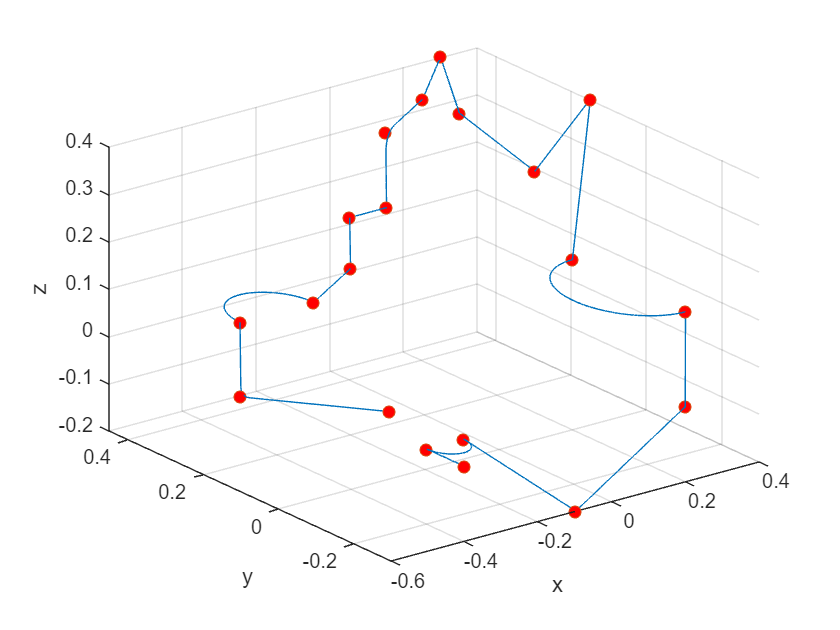

P1dotdot = (s1dotdot.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));
P2dotdot = (s2dotdot.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));
P3_primodotdot = [-((s3dot.^2).*cos(s3/rho3))/rho3-s3dotdot.*sin(s3/rho3); -((s3dot.^2).*sin(s3/rho3))/rho3+s3dotdot.*cos(s3/rho3); zeros(1,length(s3))];
P3dotdot = R3*P3_primodotdot;
P4dotdot = (s4dotdot.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));
P5dotdot = (s5dotdot.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));
P6dotdot = (s6dotdot.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));
P7dotdot = (s7dotdot.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));
P8dotdot = (s8dotdot.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));
P9dotdot = (s9dotdot.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));
P10dotdot = (s10dotdot.*(p(:,11)-p(:,10)))/norm(p(:,11)-p(:,10));
P11dotdot = (s11dotdot.*(p(:,12)-p(:,11)))/norm(p(:,12)-p(:,11));
P12dotdot = (s12dotdot.*(p(:,13)-p(:,12)))/norm(p(:,13)-p(:,12));
P13dotdot = (s13dotdot.*(p(:,14)-p(:,13)))/norm(p(:,14)-p(:,13));
P14_primodotdot = [-((s14dot.^2).*cos(s14/rho14))/rho14-s14dotdot.*sin(s14/rho14); -((s14dot.^2).*sin(s14/rho14))/rho14+s14dotdot.*cos(s14/rho14); zeros(1,length(s14))];
P14dotdot = R14*P14_primodotdot;
P15dotdot = (s15dotdot.*(p(:,16)-p(:,15)))/norm(p(:,16)-p(:,15));
P16dotdot = (s16dotdot.*(p(:,17)-p(:,16)))/norm(p(:,17)-p(:,16));
P17dotdot = (s17dotdot.*(p(:,18)-p(:,17)))/norm(p(:,18)-p(:,17));
P18_primodotdot = [-((s18dot.^2).*cos(s18/rho18))/rho18-s18dotdot.*sin(s18/rho18); -((s18dot.^2).*sin(s18/rho18))/rho18+s18dotdot.*cos(s18/rho18); zeros(1,length(s18))];
P18dotdot = R18*P18_primodotdot;
P19dotdot = (s19dotdot.*(p(:,20)-p(:,19)))/norm(p(:,20)-p(:,19));

P_Adotdot = P1dotdot+P2dotdot;
P_Bdotdot = P4dotdot+P5dotdot+P6dotdot+P7dotdot+P8dotdot+P9dotdot+P10dotdot+P11dotdot+P12dotdot+P13dotdot;
P_Cdotdot = P15dotdot+P16dotdot+P17dotdot;
P_Ddotdot = P19dotdot;

Pdotdot = [P_Adotdot(:,1:t3*1000) P3dotdot(:,t3*1000+1:t4*1000) P_Bdotdot(:,t4*1000+1:t14*1000) P14dotdot(:,t14*1000+1:t15*1000) P_Cdotdot(:,t15*1000+1:t18*1000) P18dotdot(:,t18*1000+1:t19*1000) P_Cdotdot(:,t19*1000+1:end) ];

%Grafico traiettoria nello spazio operativo
figure
plot3(P(1,:),P(2,:),P(3,:))
hold on
scatter3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','r')
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold off

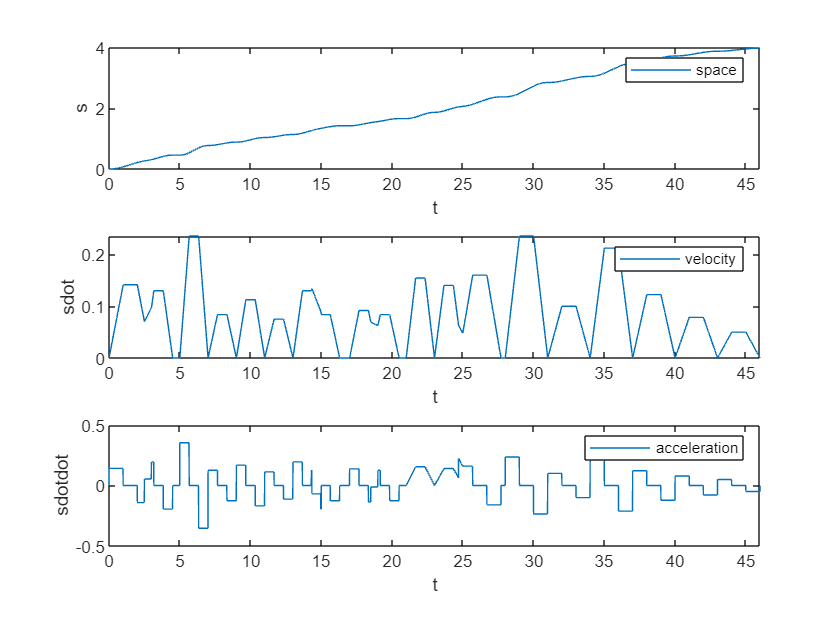

%Grafici di s, sdot ed sdotdot
s = s1+s2+s3+s4+s5+s6+s7+s8+s9+s10+s11+s12+s13+s14+s15+s16+s17+s18+s19;
sdot = s1dot+s2dot+s3dot+s4dot+s5dot+s6dot+s7dot+s8dot+s9dot+s10dot+s11dot+s12dot+s13dot+s14dot+s15dot+s16dot+s17dot+s18dot+s19dot;
sdotdot = s1dotdot+s2dotdot+s3dotdot+s4dotdot+s5dotdot+s6dotdot+s7dotdot+s8dotdot+s9dotdot+s10dotdot+s11dot+s12dot+s13dotdot+s14dotdot+s15dotdot+s16dotdot+s17dotdot+s18dotdot+s19dotdot;

t=linspace(0,t20,t20*1000+1);
figure
subplot(3,1,1)
plot(t,s)
xlabel('t')
ylabel('s')
legend ("space")
xlim([0 t20])
subplot(3,1,2)
plot(t,sdot)
xlabel('t')
ylabel('sdot')
legend ("velocity")
xlim([0 t20])
subplot(3,1,3)
plot(t,sdotdot)
xlabel('t')
ylabel('sdotdot')
legend ("acceleration")
xlim([0 t20])

## ORIENTATION

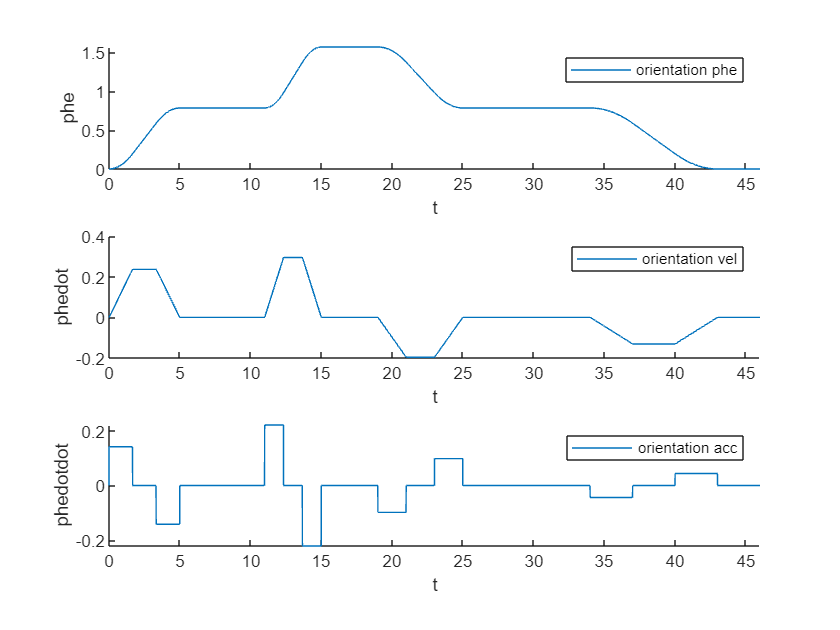

%% Orientamento
phi = [0 pi/4 pi/2 pi/4 0];

[phi1 ,phi1dot, phi1dotdot] = profile(phi(1),phi(2),t1,t3,t20,0,0,0,0,0);
[phi2 ,phi2dot, phi2dotdot] = profile(phi(2),phi(3),t6,t8,t20,0,0,0,0,0);
[phi3 ,phi3dot, phi3dotdot] = profile(phi(3),phi(4),t10,t13,t20,0,0,0,0,0);
[phi4 ,phi4dot, phi4dotdot] = profile(phi(4),phi(5),t16,t19,t20,0,0,0,0,0);

phe = phi(1)+phi1.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4.*(phi(5)-phi(4))/norm(phi(5)-phi(4));
phedot = phi1dot.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2dot.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3dot.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4dot.*(phi(5)-phi(4))/norm(phi(5)-phi(4));
phedotdot = phi1dotdot.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2dotdot.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3dotdot.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4dotdot.*(phi(5)-phi(4))/norm(phi(5)-phi(4));

t_o = linspace(0, t20, size(phe,2));
figure
subplot(3,1,1)
%igure("Name", "phe")
hold on
plot(t_o, phe);
xlabel('t')
ylabel('phe')
xlim([0 t20])
legend ("orientation phe")
% figure("Name", "phedot")
subplot(3,1,2)
hold on
plot(t_o, phedot);
xlabel('t')
ylabel('phedot')
legend ("orientation vel")
xlim([0 t20])
subplot(3,1,3)
%figure("Name", "phedotdot")
hold on
plot(t_o, phedotdot);
xlabel('t')
ylabel('phedotdot')
xlim([0 t20])
legend ("orientation acc")
hold off

## REFERENCES FOR POSITION AND ORIENTATION

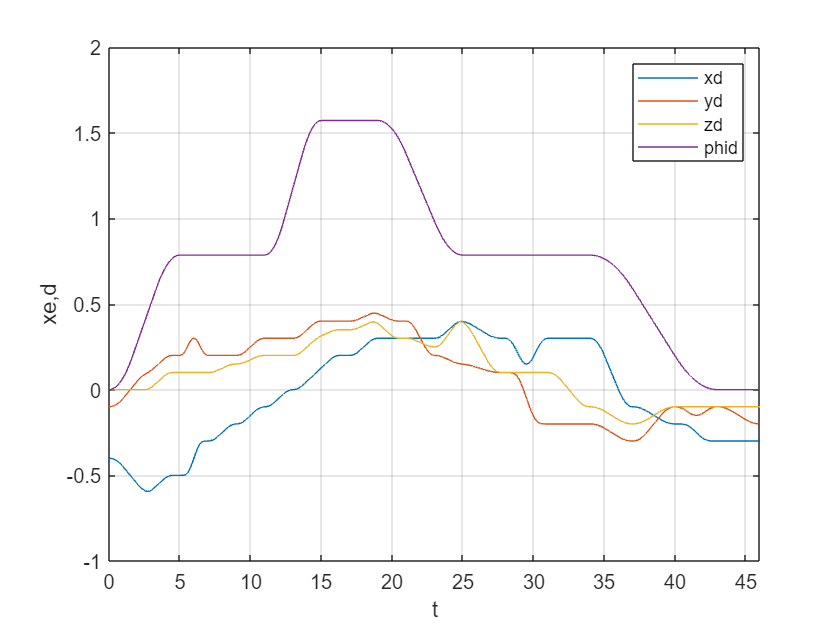

t=linspace(0,t20,t20*1000+1);

xd = timeseries([P;phe],t);
xddot = timeseries([Pdot;phedot],t);
xddotdot = timeseries([Pdotdot;phedotdot],t);

%Grafico xd
figure
plot(t,P);
hold on
plot(t,phe);
xlabel('t')
ylabel('xe,d')
legend('xd','yd','zd','phid')
xlim([0 t20])
grid on

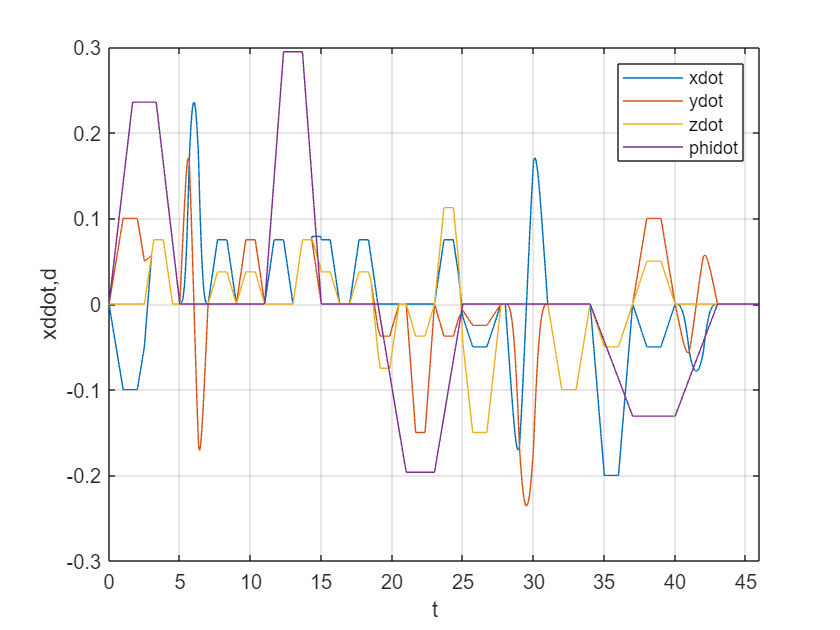

%Grafico xddot
figure
plot(t,Pdot);
hold on
plot(t,phedot);
xlabel('t')
ylabel('xddot,d')
legend('xdot','ydot','zdot','phidot')
xlim([0 t20])
grid on

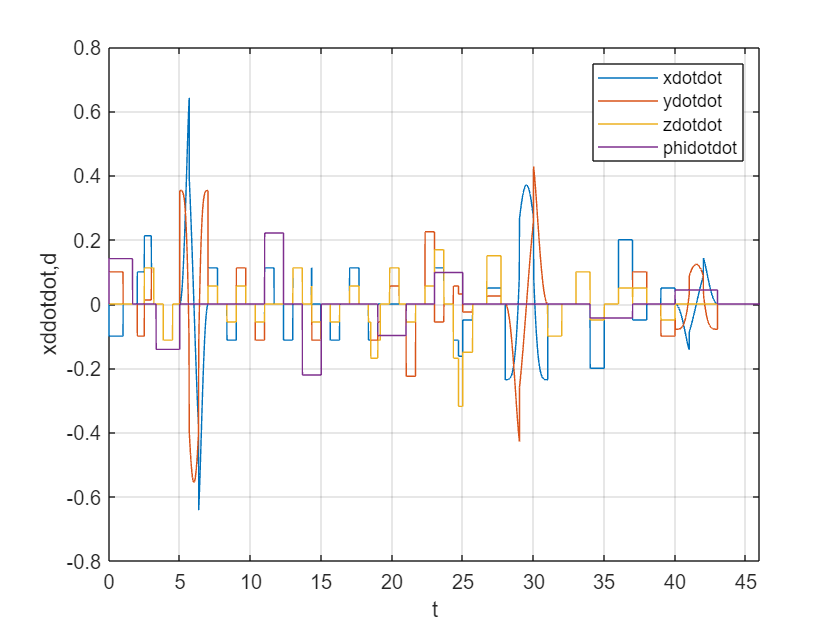

%Grafico xddotdot
figure
plot(t,Pdotdot);
hold on
plot(t,phedotdot);
xlabel('t')
ylabel('xddotdot,d')
legend('xdotdot','ydotdot','zdotdot','phidotdot')
xlim([0 t20])
grid on

## **CLIK ALGORITHMS**

**CLIK con inversa dello jacobiano**

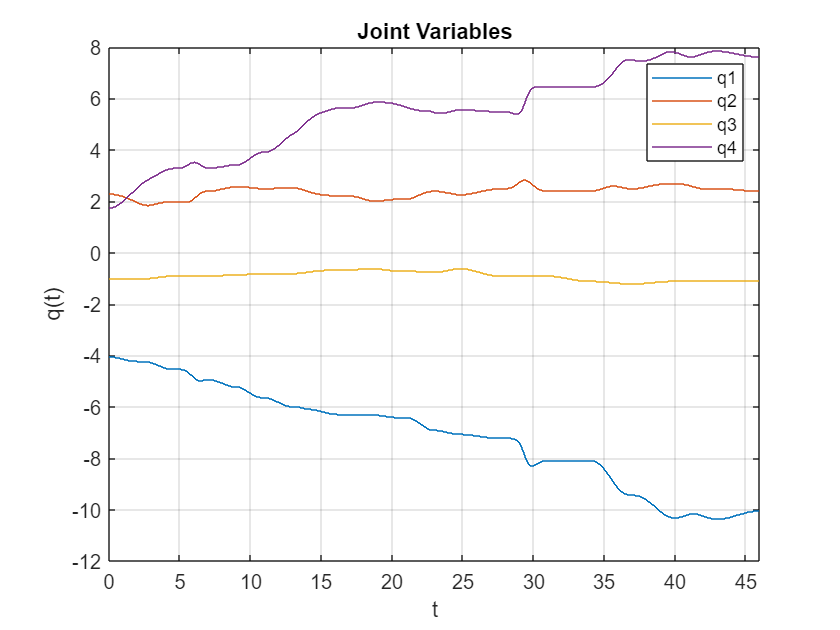

K = diag([1000 1000 700 500]);
q0=[-4.0424 2.2916 -1.0000 1.7508];

out=sim("clik_inv.slx");
%Grafico variabili di giunto
figure
plot(q)
title ('Joint Variables')
xlabel('t')
ylabel('q(t)')
xlim([0 t20])
legend('q1','q2','q3','q4')
grid on

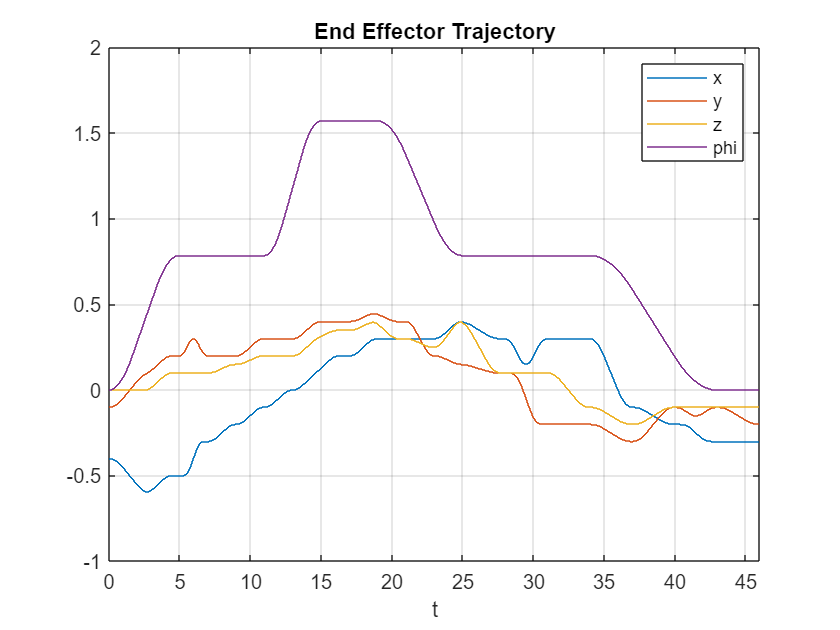

%Grafici traiettoria effettiva dell'end effector
figure
plot(xe)
title ('End Effector Trajectory')
xlabel('t');
ylabel('')
legend('x','y','z','phi')
xlim([0 t20])
grid on

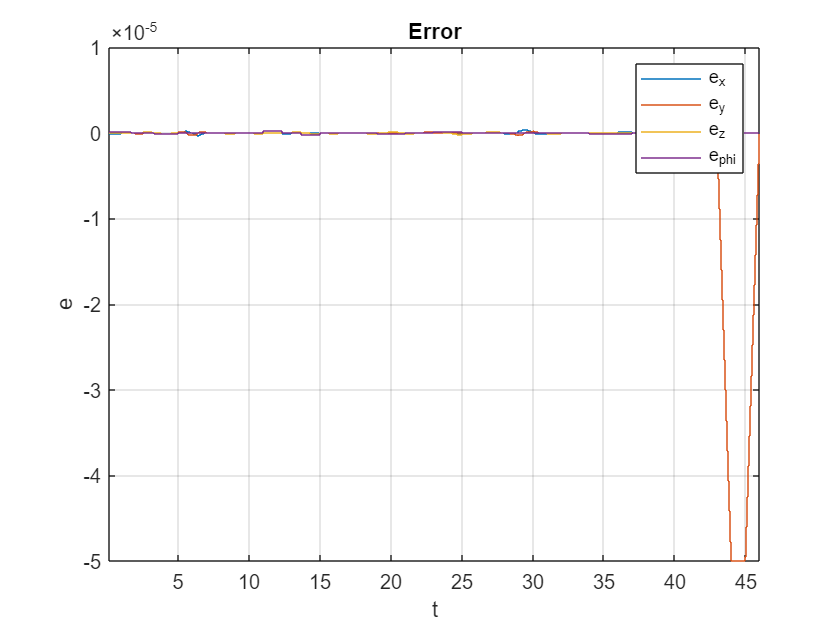

%Grafico dinamica dell'errore
figure
plot(e)
title ('Error')
xlabel('t');
ylabel('e');
xlim([0.1 t20])
legend('e_x','e_y','e_z','e_phi')
grid on
hold off

% %Calcolo misura di manipolabilità
w_inv = (sin(q.data(2,:))).^2;
w_inv = w_inv(:,1:46001);

**CLIK con trasposta dello Jacobiano**

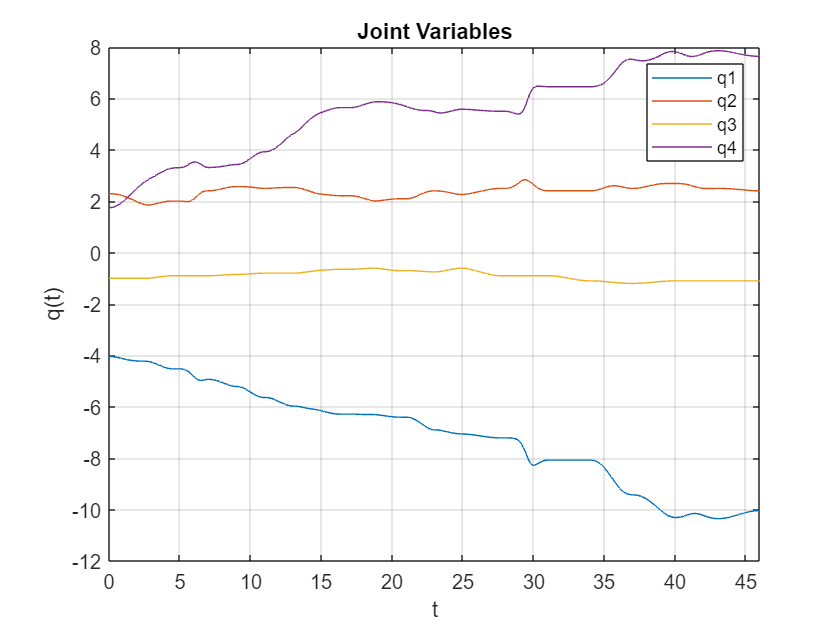

K_trasp = diag([550 800 200 200]);
out=sim("clik_transp.slx");
%Grafico variabili di giunto
figure
plot(out.tout,out.q_trasp.signals.values(:,:))
title ('Joint Variables')
xlabel('t')
ylabel('q(t)')
xlim([0 t20])
legend('q1','q2','q3','q4')
grid on

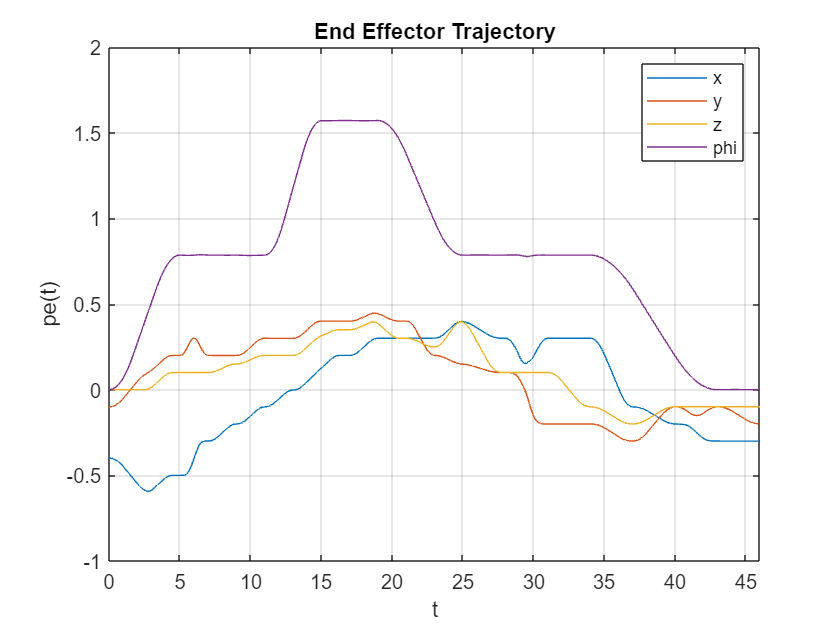

%Grafici traiettoria effettiva dell'end effector
figure
plot(out.tout,out.xe_trasp.signals.values(:,:))
title ('End Effector Trajectory')
xlabel('t');
ylabel('pe(t)')
legend('x','y','z','phi')
xlim([0 t20])
grid on

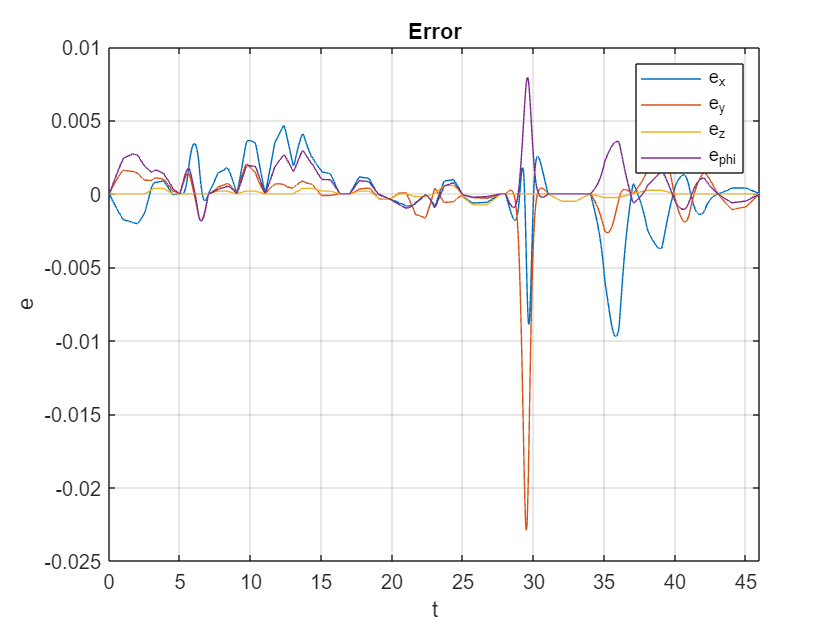

%Grafico dinamica dell'errore
figure
plot(out.tout,out.e_trasp.signals.values(:,:))
title ('Error')
xlabel('t');
ylabel('e');
xlim([0 t20])
legend('e_x','e_y','e_z','e_phi')
grid on
hold off

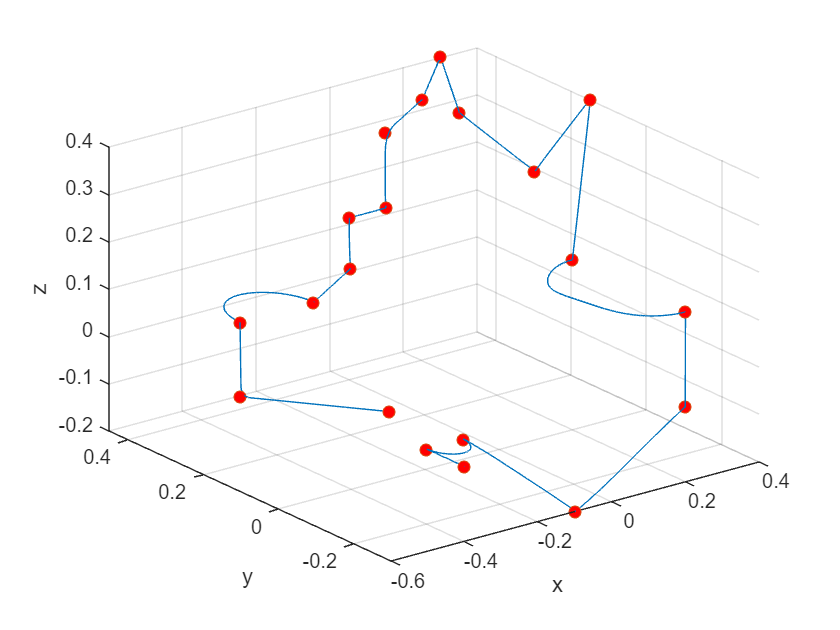

figure
plot3(out.xe_trasp.signals.values(1,:),out.xe_trasp.signals.values(2,:),out.xe_trasp.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','r')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

%Calcolo misura di manipolabilità
%w_trasp = (sin(out.q_trasp.signals.values(2,:,:))).^2

**CLIK con pseudo-inversa dello Jacobiano**

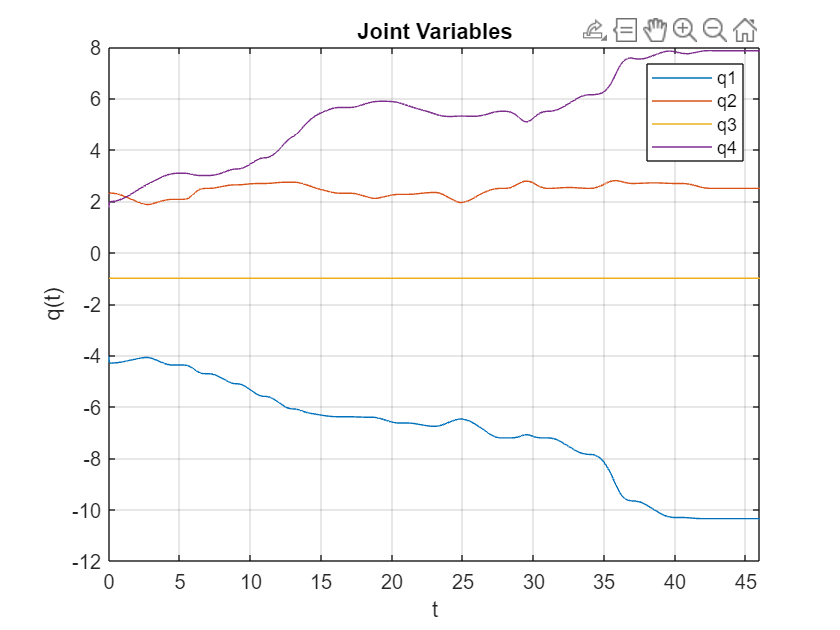

Pp = P([1,3],:);
Ppdot = Pdot([1,3],:);
xdp = timeseries([Pp;phe],t);
xdpdot = timeseries([Ppdot;phedot],t);
K_pinv = diag([70,70,70]);
k0 = 5;
out=sim("CLIK_pinv.slx");

%Grafico variabili di giunto
figure
plot(out.tout,out.q_pinv.signals.values(:,:))
title ('Joint Variables')
xlabel('t')
ylabel('q(t)')
xlim([0 t20])
legend('q1','q2','q3','q4')
grid on

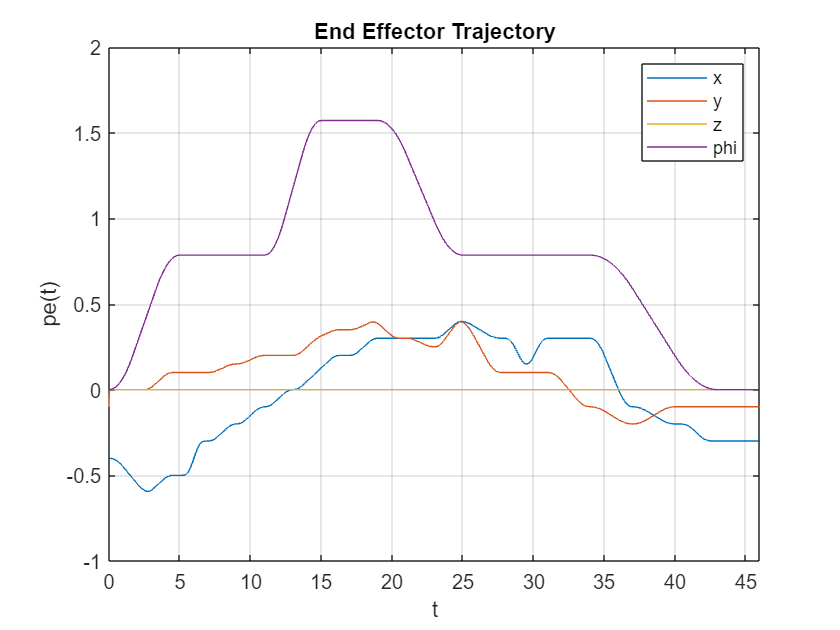

%Grafici traiettoria effettiva dell'end effector
figure
plot(out.tout,out.xe_pinv.signals.values(:,:))
title ('End Effector Trajectory')
xlabel('t');
ylabel('pe(t)')
legend('x','y','z','phi')
xlim([0 t20])
grid on

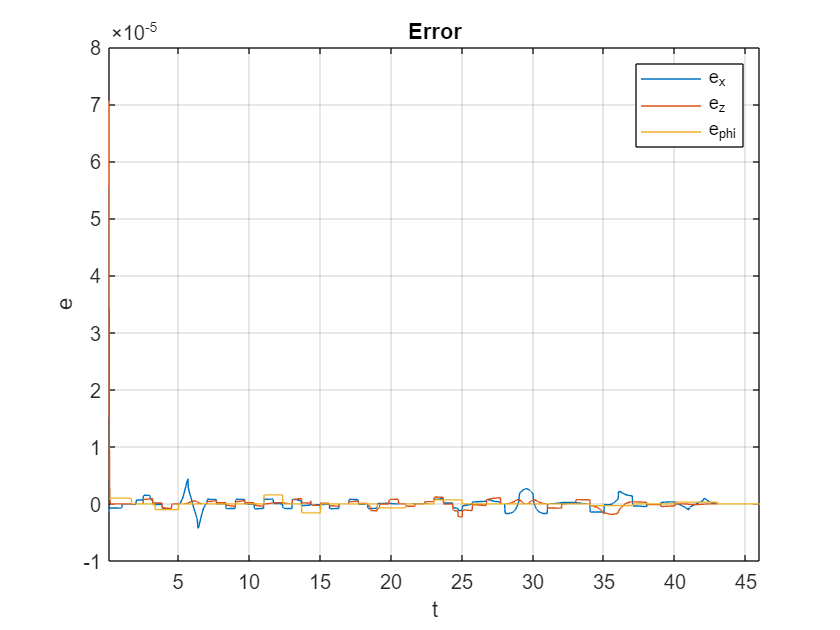

%Grafico dinamica dell'errore
figure
plot(out.tout,out.e_pinv.signals.values(:,:))
title ('Error')
xlabel('t');
ylabel('e');
xlim([0.1 t20])
legend('e_x','e_z','e_phi')
grid on
hold off

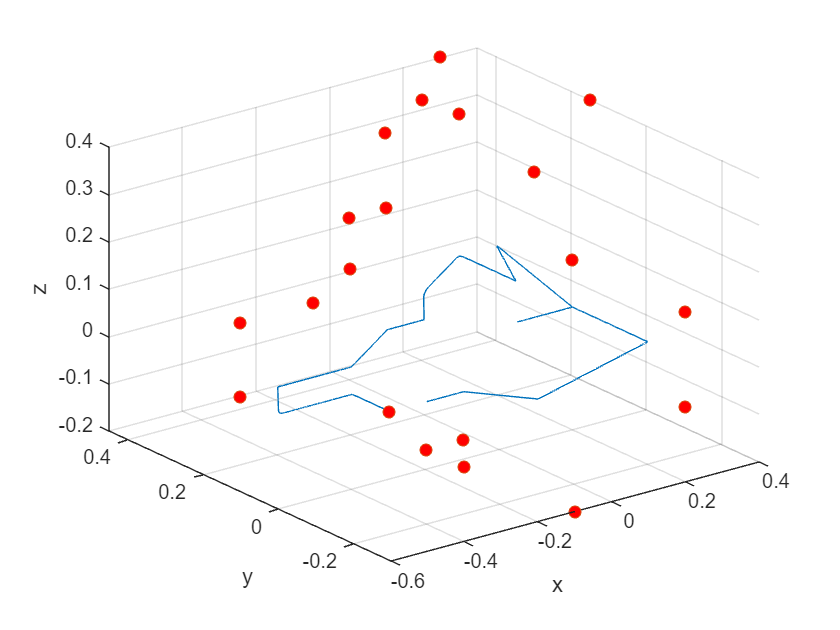

figure
plot3(out.xe_pinv.signals.values(1,:),out.xe_pinv.signals.values(2,:),out.xe_pinv.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','r')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

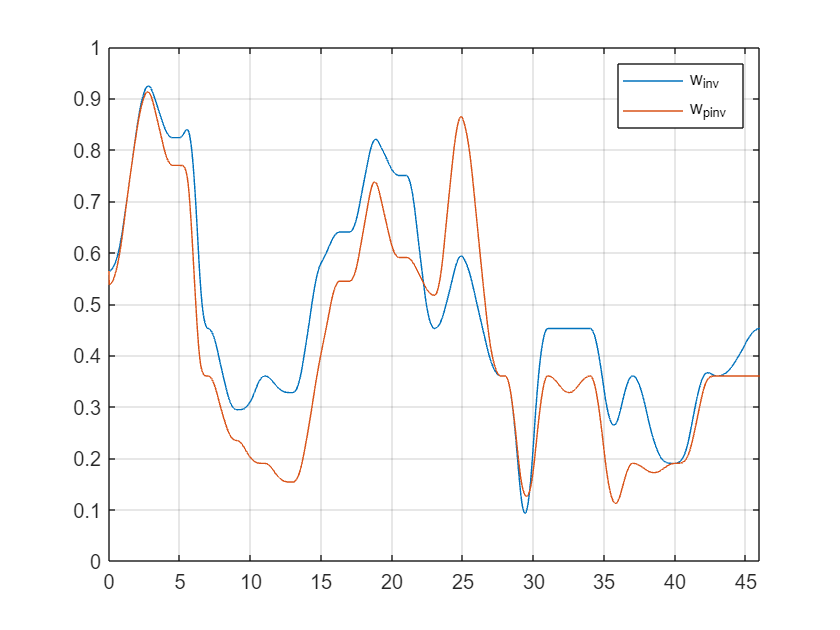

%Calcolo misura di manipolabilità
w_pinv = (sin(out.q_pinv.signals.values(2,:))).^2;
w_pinv = w_pinv(:,1:46001);
figure
plot(t,w_inv)
xlim([0 t20])
hold on
xlim([0 t20])
plot(t,w_pinv)
legend("w_inv", "w_pinv")
grid on

**Second Order CLIK Algorithm**

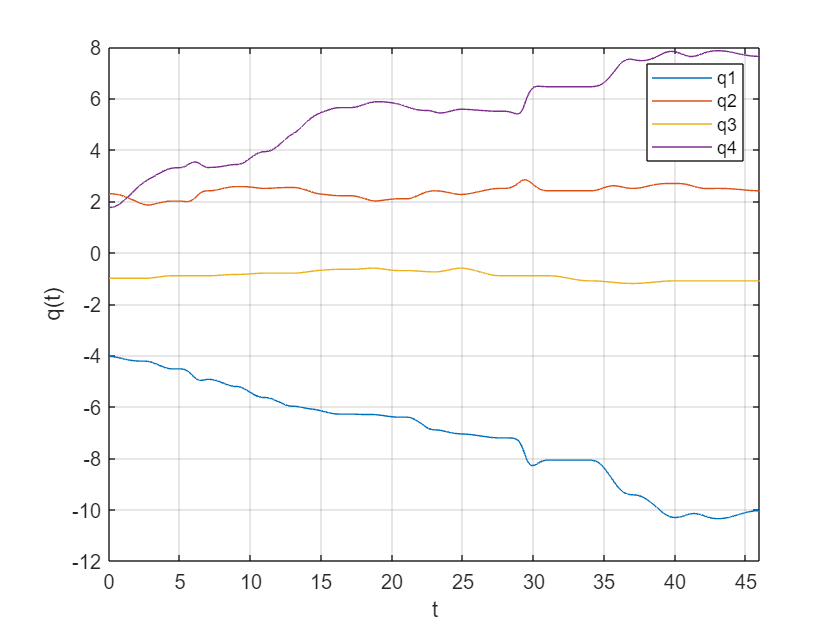

Kp = diag([3500,3000,3000,3500]);
Kd = diag([70 70 70 70]);
out=sim("CLIK_2_order.slx");
qd = timeseries(out.q_sec.signals.values(:,:),out.tout);
qddot = timeseries(out.qdot_sec.signals.values(:,:),out.tout);
qddotdot = timeseries(out.qdotdot_sec.signals.values(:,:),out.tout);

%Grafico variabili di giunto
figure
plot(out.tout,out.q_sec.signals.values(:,:))
xlabel('t')
ylabel('q(t)')
xlim([0 t20])
legend('q1','q2','q3','q4')
grid on

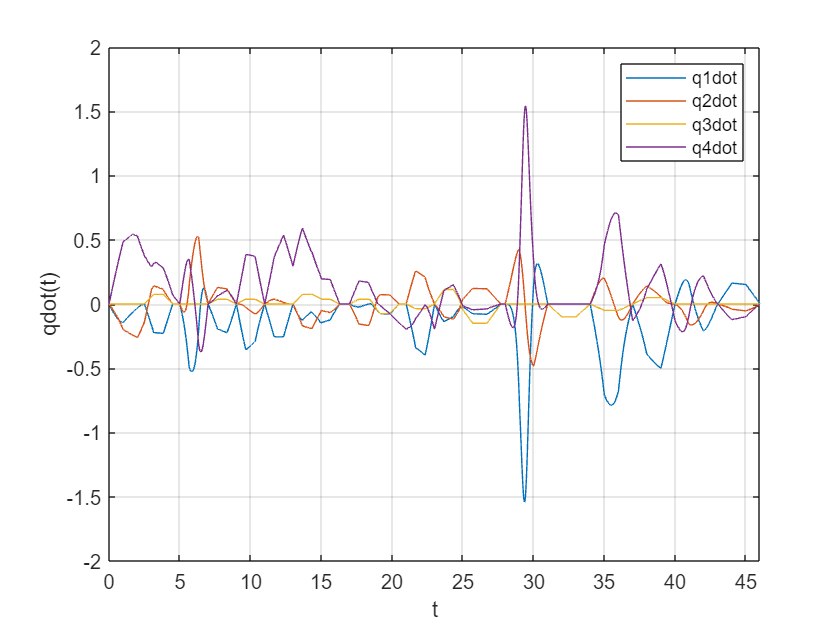

%Grafico variabili di giunto (velocità)
figure
plot(out.tout,out.qdot_sec.signals.values(:,:))
xlabel('t')
ylabel('qdot(t)')
xlim([0 t20])
legend('q1dot','q2dot','q3dot','q4dot')
grid on

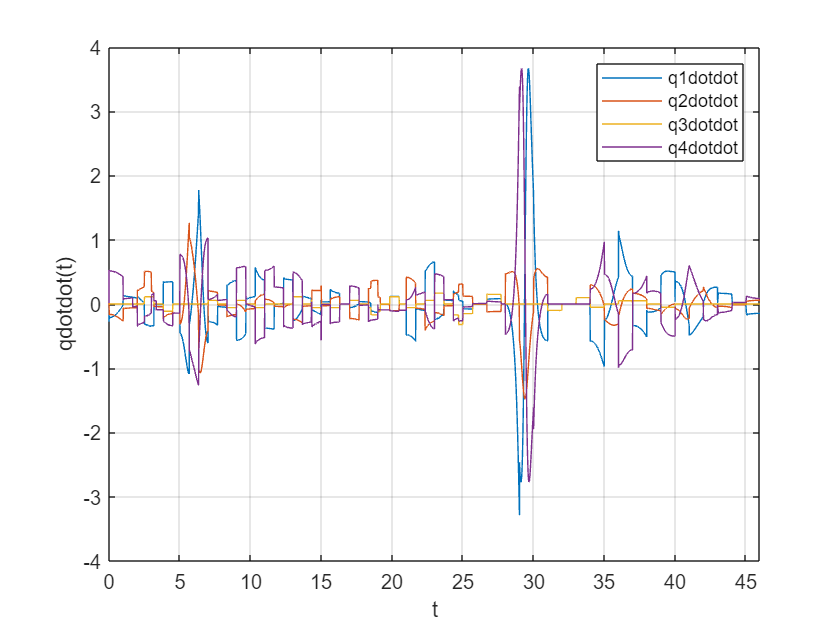

%Grafico variabili di giunto (accelerazione)
figure
plot(out.tout,out.qdotdot_sec.signals.values(:,:))
xlabel('t')
ylabel('qdotdot(t)')
xlim([0 t20])
legend('q1dotdot','q2dotdot','q3dotdot','q4dotdot')
grid on

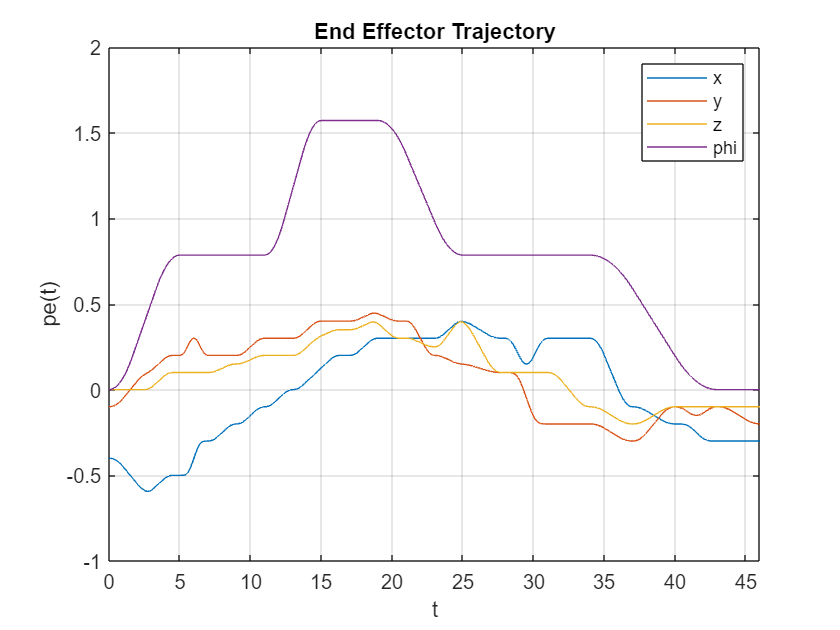

%Grafico traiettoria effettiva dell'end effector
figure
plot(out.tout,out.xe_sec.signals.values(:,:))
title ('End Effector Trajectory')
xlabel('t');
ylabel('pe(t)')
legend('x','y','z','phi')
xlim([0 t20])
grid on

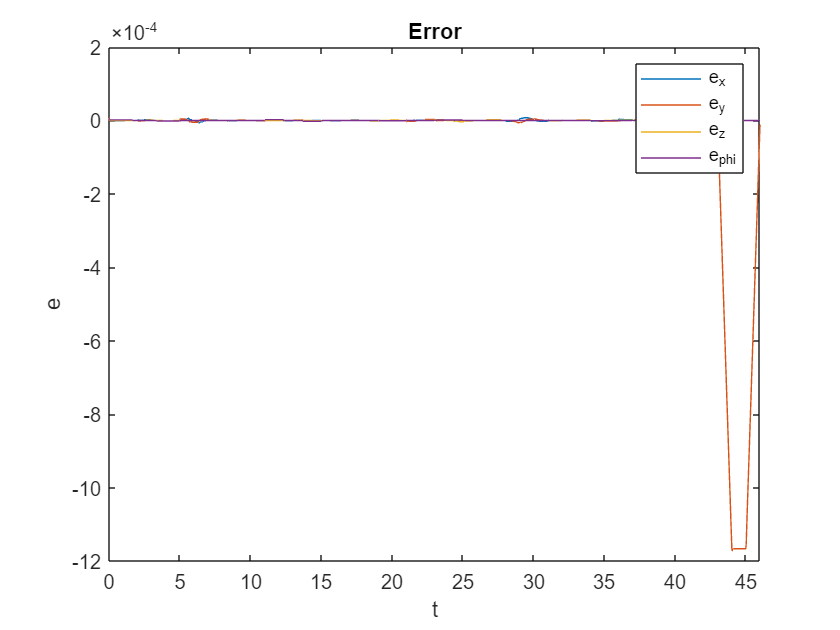

%Grafico dinamica dell'errore
figure
plot(out.tout,out.e_sec.signals.values(:,:))
title ('Error')
xlabel('t');
ylabel('e');
xlim([0 t20])
legend('e_x','e_y','e_z','e_phi')

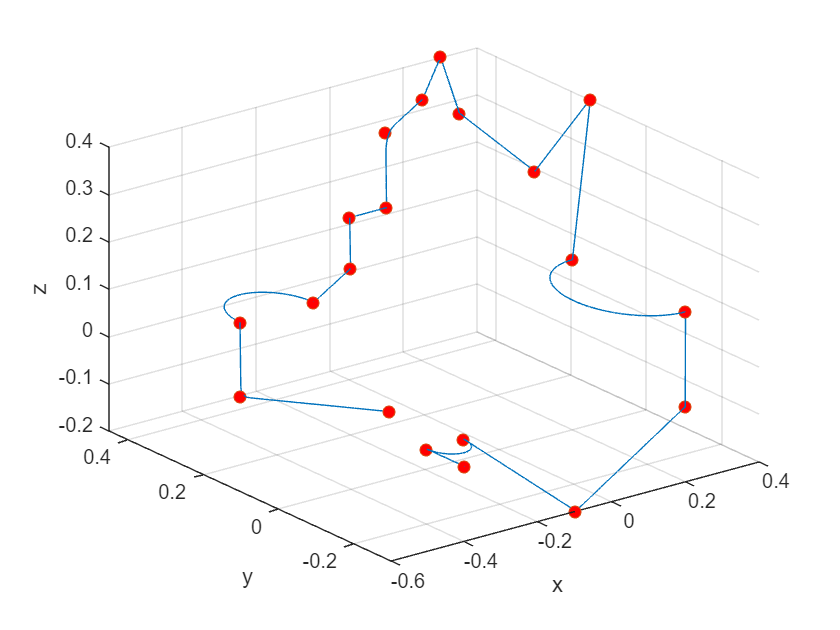

figure
plot3(out.xe_sec.signals.values(1,:),out.xe_sec.signals.values(2,:),out.xe_sec.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','r')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

## ROBUST CONTROL

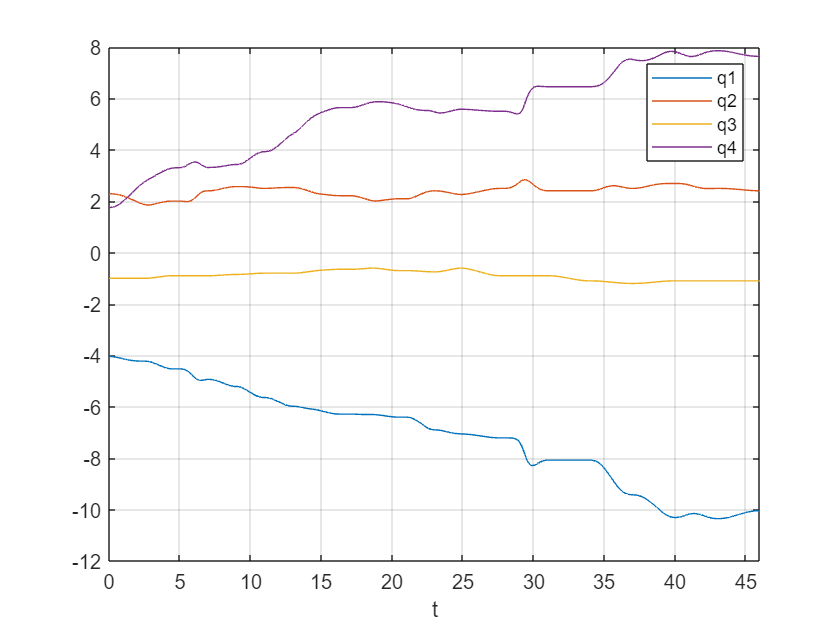

%% Controllo robusto
Kp_c = diag([1500 1500 10000 4500]); %l'erroe sulla x è molto elevato e quindi alzo Kp
Kd_c = diag([100 100 100 100]);
D = [zeros(4,4);eye(4)];
Q = [zeros(4) zeros(4)* 1000;
    eye(4)*10 zeros(4)]; %è piu importante diminuire l'errore di posizione Q2>>Q3

eps = 0.00001; 
rho_vers = 3; 
ml = 3; %carico da aggiungere alla massa del 3° link

out=sim("controllo_robusto.slx");
%%
figure

plot(out.control.time,out.qcont.signals.values(:,:))
xlabel('t');
legend('q1','q2','q3','q4')
xlim([0 t20])
grid on

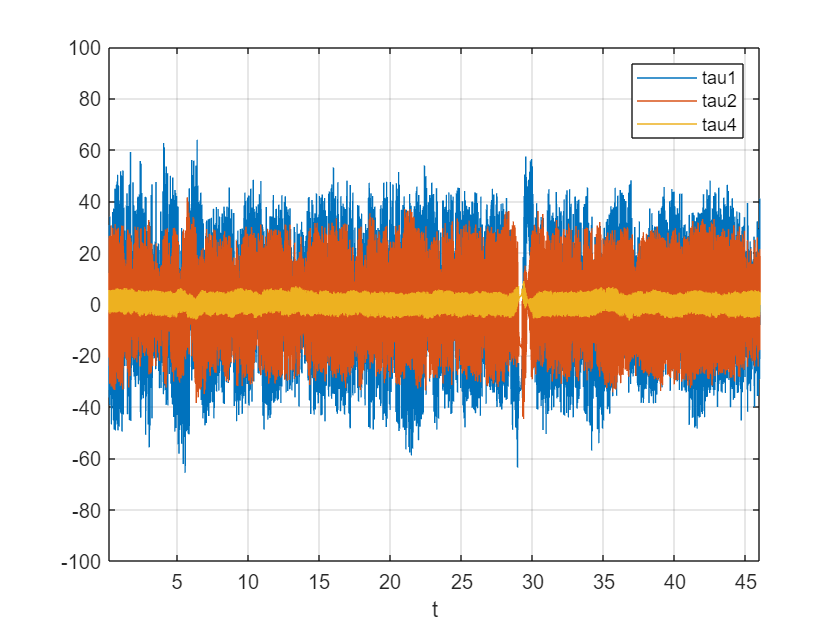

%saveas(gcf, 'c_q_robusto.jpeg', 'jpeg');
figure
plot(out.control.time,out.control.signals.values(1:2,:))

xlabel('t');
xlim([0 t20])
grid on
hold on
plot(out.control.time,out.control.signals.values(4,:))
legend('tau1','tau2','tau4')
%saveas(gcf, 'c_tau_robusto.jpeg', 'jpeg');

xlim([0.2 t20])
ylim([-100 100])

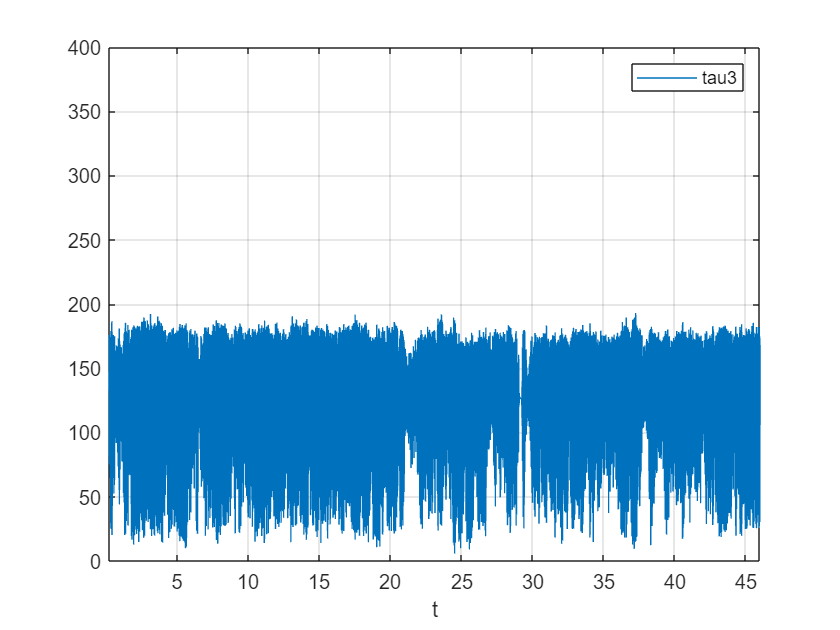

figure
plot(out.control.time,out.control.signals.values(3,:))
xlabel('t');
xlim([0.2 t20])
ylim([0,400])
grid on
legend('tau3')

%saveas(gcf, 'c_tau_3_robusto.jpeg', 'jpeg');
MAX_TAU_RC=[norm(out.control.signals.values(1,20:end), Inf) 
norm(out.control.signals.values(2,20:end), Inf)
 norm(out.control.signals.values(3,20:end), Inf)
 norm(out.control.signals.values(4,20:end), Inf)]

MAX_TAU_RC =    65.6695
   44.7161
  193.0186
    8.9553


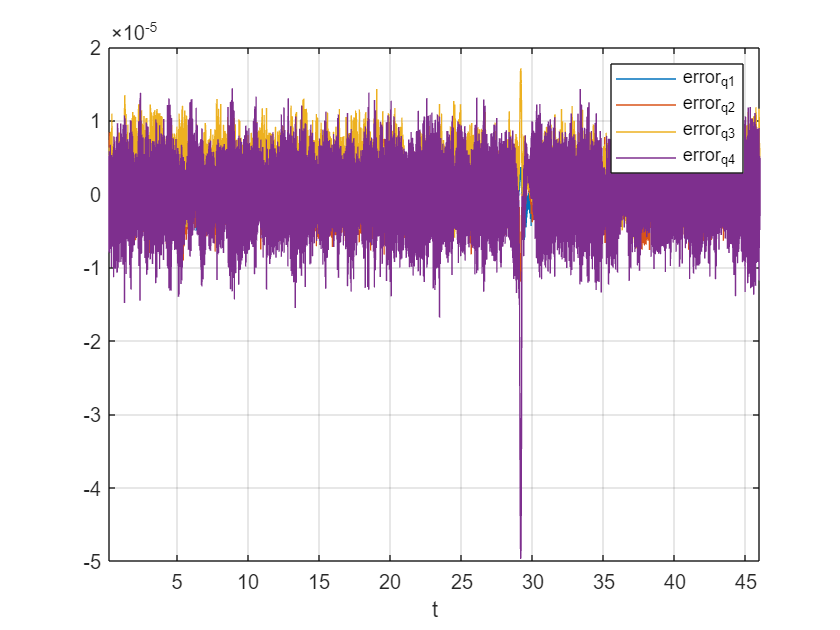

figure
plot(out.control.time(10:end),out.qerror.signals.values(:,10:end))
legend('error_q1','error_q2','error_q3','error_q4')
xlim([0.2 t20])
grid on
xlabel('t');

%saveas(gcf, 'c_error_robusto.jpeg', 'jpeg');
MAX_ERR_RC=[norm(out.qerror.signals.values(1,20:end), Inf) 
 norm(out.qerror.signals.values(2,20:end), Inf)
 norm(out.qerror.signals.values(3,20:end), Inf)
 norm(out.qerror.signals.values(4,20:end), Inf)]

MAX_ERR_RC = 1.0e-04 *

    0.0704
    0.1197
    0.1709
    0.4970


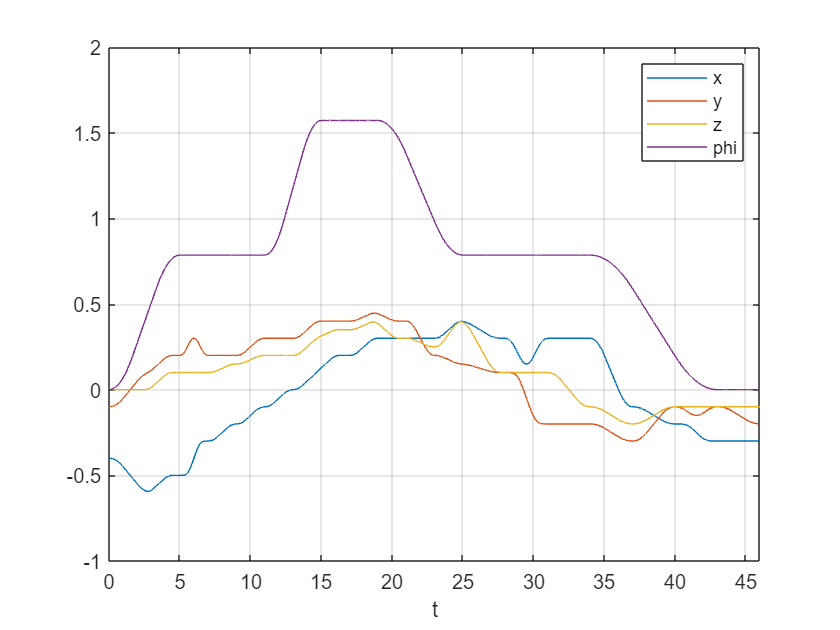

figure
plot(out.control.time,out.xecont.signals.values(:,:))
xlim([0 t20])
xlabel('t');
grid on
legend('x','y','z','phi')

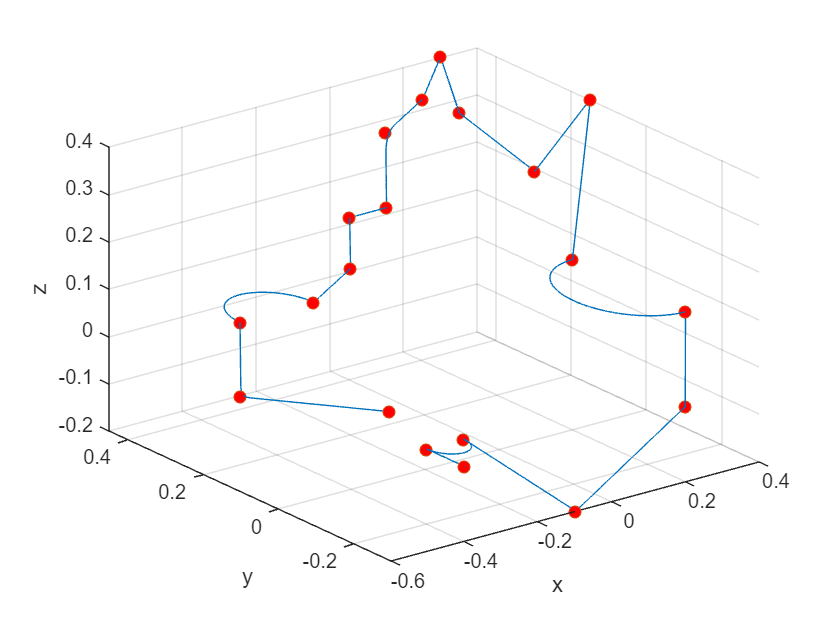

%saveas(gcf, 'c_op_robusto.jpeg', 'jpeg');

figure
plot3(out.xecont.signals.values(1,:),out.xecont.signals.values(2,:),out.xecont.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','r')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

## ADAPTIVE CONTROL

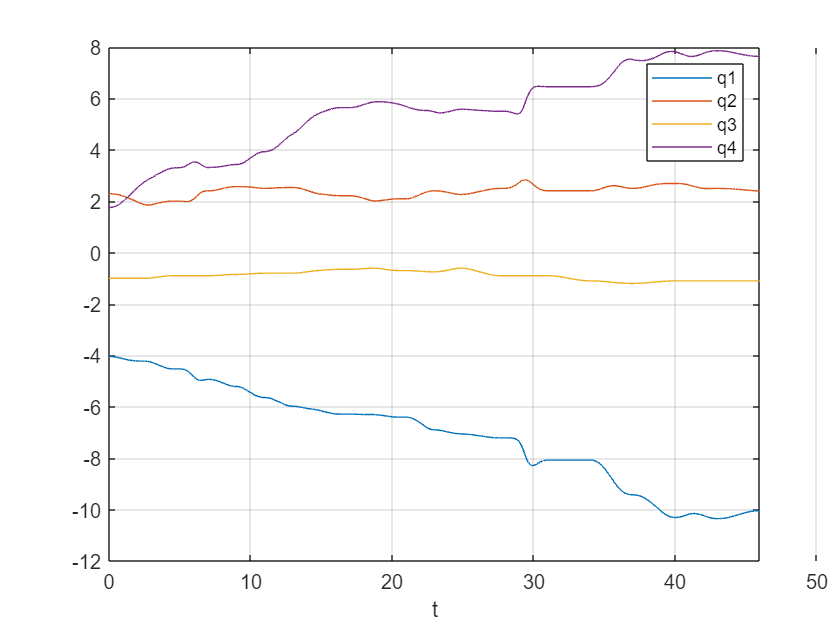

%% Controllo adattativo
lambda=diag([200,200,200,200]);
K_pi=diag([10,10,10,10,10,10,10,10,10,10,10,0.001,10,10,10]);
Kd_c_ad=diag([400,400,800,400]);
%scelgo il valore in corrispondenza di ml4 piu piccolo (poi calcolo l'inversa) 
% per fare in modo che il tempo di assestamento del parametro sia piccolo
ml1=20;
ml2=20;
ml3=10;
ml4=0;
Il1=4;
Il2=4;
Il4=1;
kr1=1;
kr2=1;
kr3=50;
kr4=20;
Im1=0.01;
Im2=0.01;
Im3=0.005;
Im4=0.001;
Fm1=0.00005;
Fm2=0.00005;
Fm3=0.01;
Fm4=0.005;

pi0=[ml1 Il1 Im1 Fm1 ml2 Il2 Im2 Fm2 ml3 Im3 Fm3 ml4 Il4 Im4 Fm4]';

out=sim("Controllo_adattativo.slx");

%%
figure
plot(out.controlad.time,out.qcontad.signals.values(:,:))
legend('q1','q2','q3','q4')
xlabel('t');
xlim([0 t20])
grid on

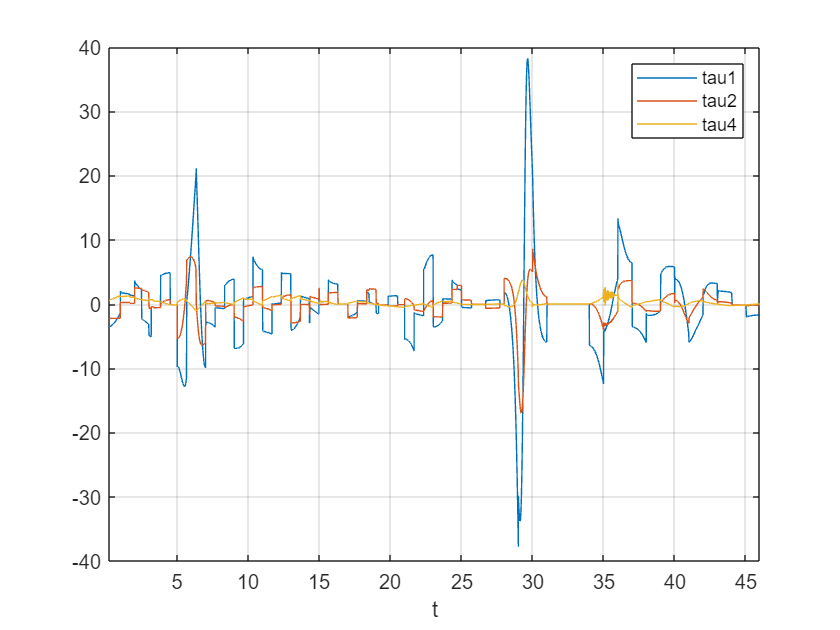

%saveas(gcf, 'Adattativo_q.jpeg', 'jpeg');
figure
plot(out.controlad.time,out.controlad.signals.values(1:2,:))
xlabel('t');
xlim([0.2 t20])
grid on
hold on
plot(out.controlad.time,out.controlad.signals.values(4,:))
legend('tau1','tau2','tau4')

%saveas(gcf, 'Adattativo_tau.jpeg', 'jpeg');
MAX_TAU_AC=[norm(out.controlad.signals.values(1,20:end), Inf) 
 norm(out.controlad.signals.values(2,20:end), Inf)
 norm(out.controlad.signals.values(3,20:end), Inf)
 norm(out.controlad.signals.values(4,20:end), Inf)]

MAX_TAU_AC =    38.1932
   16.9898
  134.5640
    3.7253


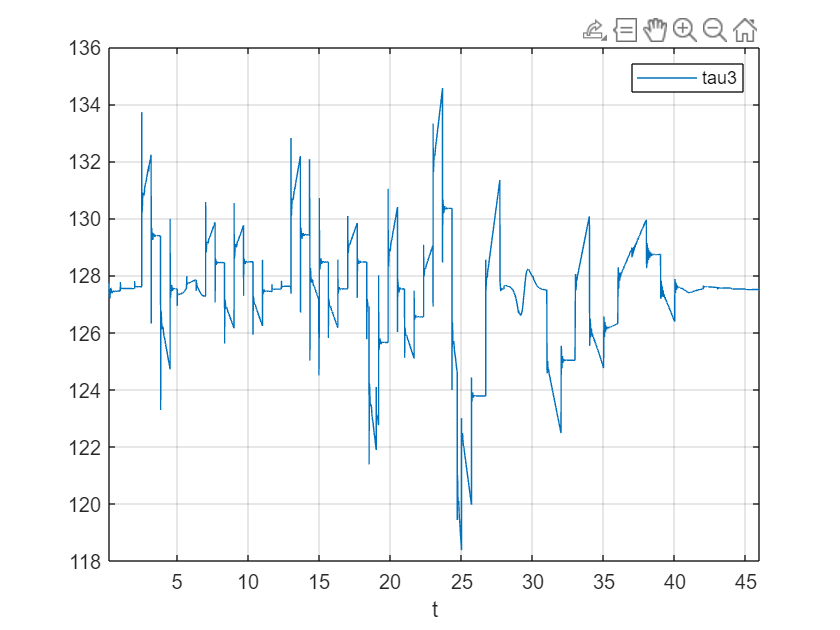

figure
plot(out.controlad.time,out.controlad.signals.values(3,:))
xlabel('t');
xlim([0.2 t20])
grid on
legend('tau3')

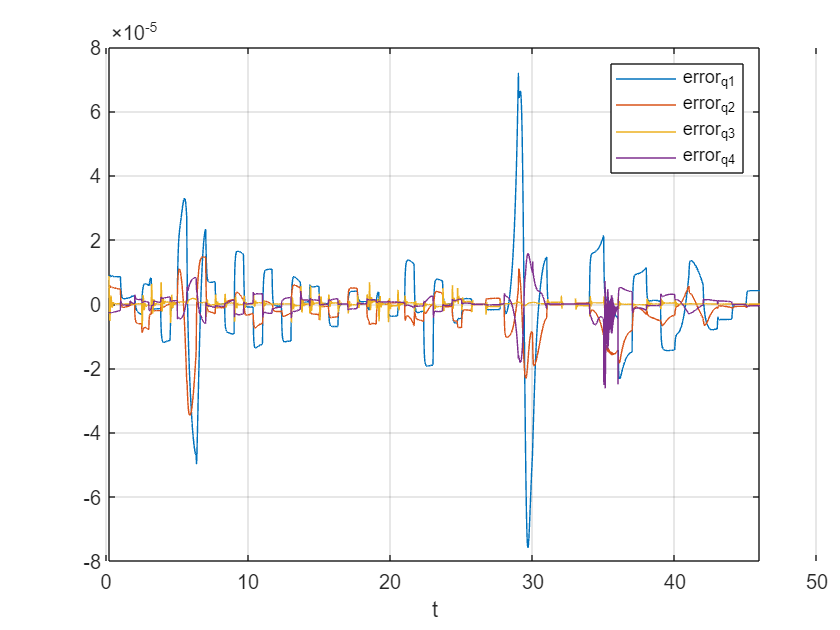

%saveas(gcf, 'Adattativo_tau3.jpeg', 'jpeg');
figure
plot(out.controlad.time,out.qerrorad.signals.values(:,:))
xlabel('t');
xlim([0.2 t20])
grid on
legend('error_q1','error_q2','error_q3','error_q4')

%saveas(gcf, 'Adattativo_error.jpeg', 'jpeg');
MAX_ERR_AC=[norm(out.qerrorad.signals.values(1,20:end), Inf) 
 norm(out.qerrorad.signals.values(2,20:end), Inf)
 norm(out.qerrorad.signals.values(3,20:end), Inf)
 norm(out.qerrorad.signals.values(4,20:end), Inf)]

MAX_ERR_AC = 1.0e-04 *

    0.7588
    0.3467
    0.4818
    0.2623


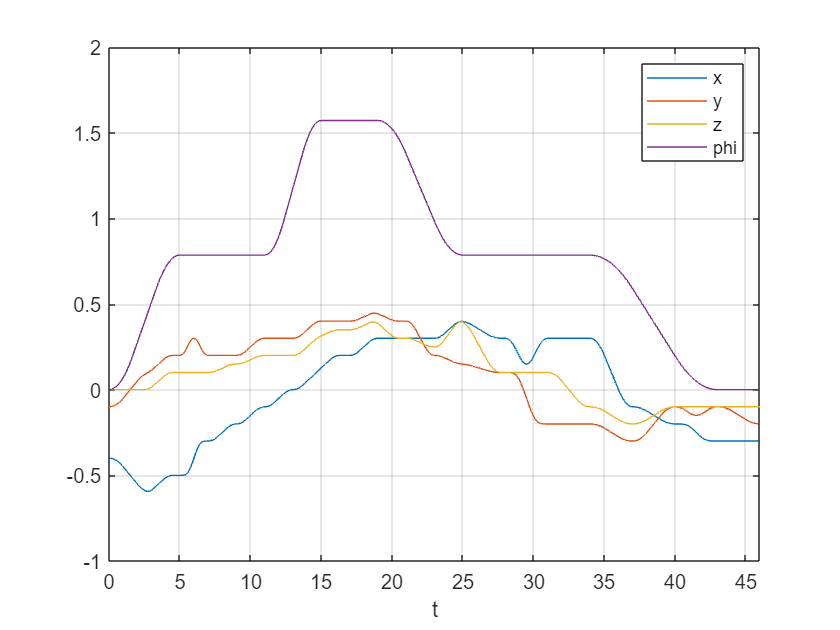

figure
plot(out.controlad.time,out.xecontad.signals.values(:,:))
xlabel('t');
xlim([0 t20])
legend('x','y','z','phi')
grid on
saveas(gcf, 'Adattativo_op.jpeg', 'jpeg');

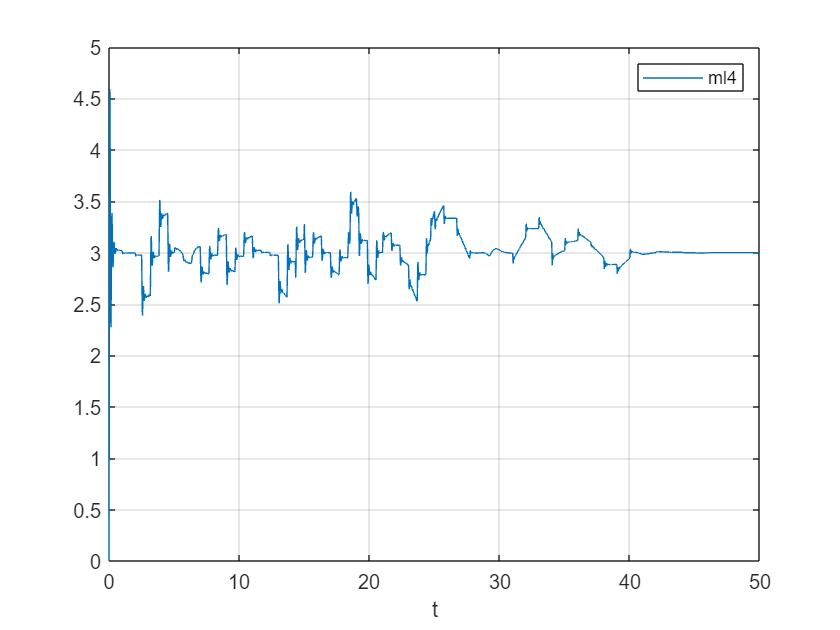

figure
plot(out.picappuccio.time,out.picappuccio.signals.values(12,:))
xlabel('t');
xlim([0 t20])
grid on
legend('ml4')
saveas(gcf, 'Adattativo_ml4.jpeg', 'jpeg');

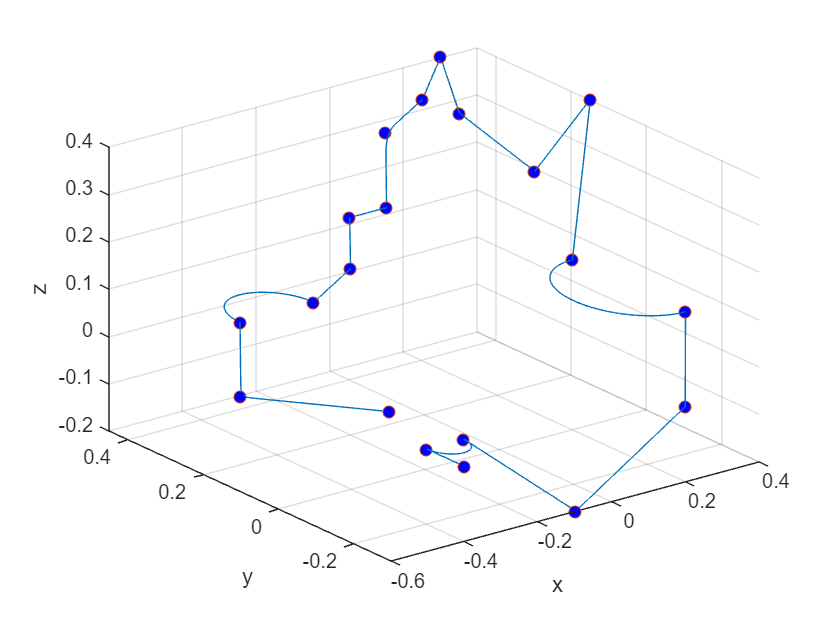

figure
plot3(out.xecontad.signals.values(1,:),out.xecontad.signals.values(2,:),out.xecontad.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','b')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

OPERATIONAL SPACE CONTROL

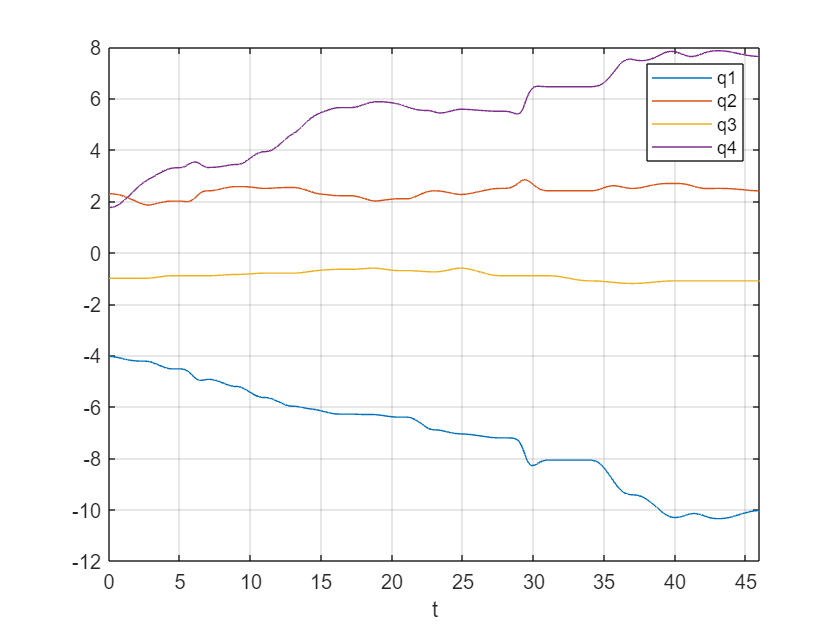

Kp_op = diag([5000 10000 10000 5000]); 
Kd_op = diag([1000 1000 1000 1000]);
Ki_op = diag([2000 4000 2000 2000]); 

out=sim("Controllo_din_inv_spazio_op");
figure
plot(out.controlinvdin.time,out.qcontinvdin.signals.values(:,:))
legend('q1','q2','q3','q4')
xlabel('t');
xlim([0 t20])
grid on

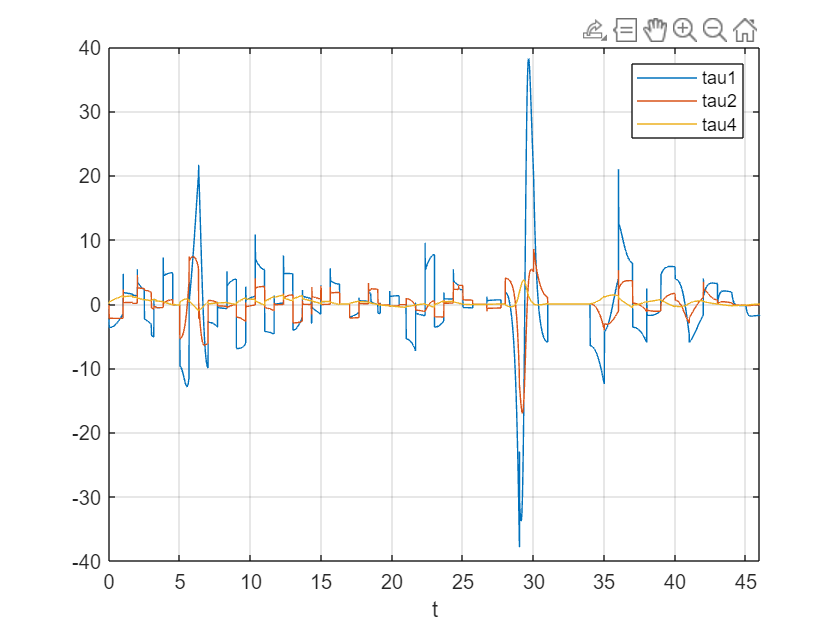

figure
plot(out.controlinvdin.time,out.controlinvdin.signals.values(1:2,:))
xlabel('t');
xlim([0 t20])
grid on
hold on
plot(out.controlinvdin.time,out.controlinvdin.signals.values(4,:))
legend('tau1','tau2','tau4')

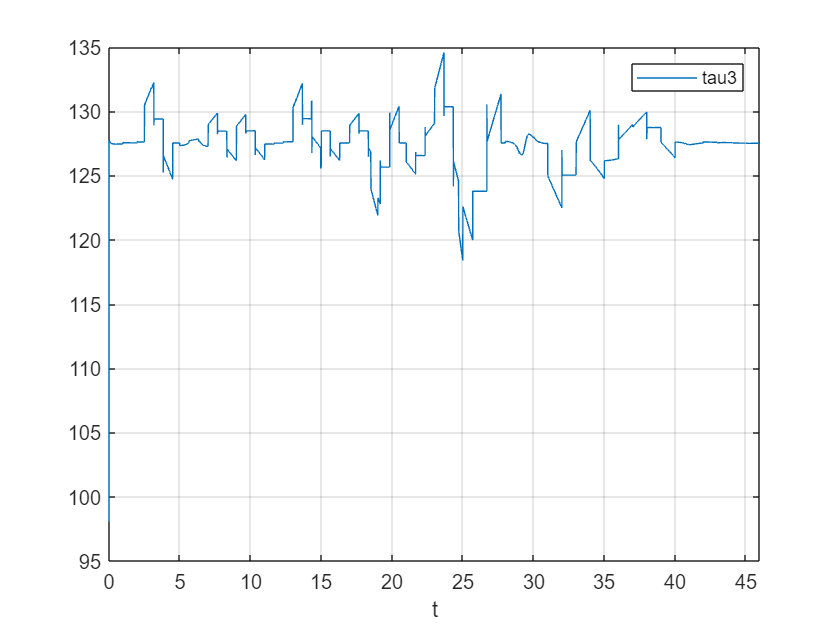

figure
plot(out.controlinvdin.time,out.controlinvdin.signals.values(3,:))
xlabel('t');
xlim([0 t20])
grid on
legend('tau3')

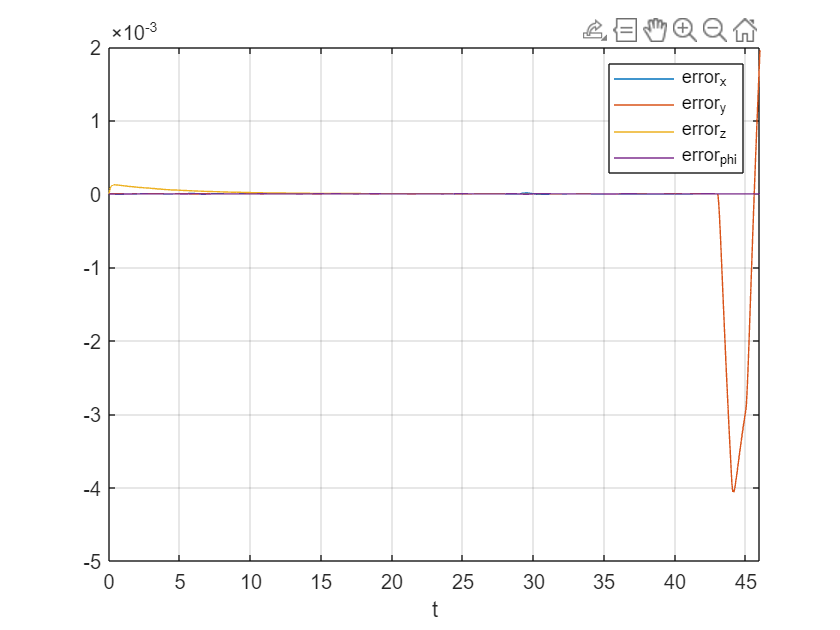


figure
plot(out.controlinvdin.time,out.errorcontinv.signals.values(:,:))
xlabel('t');
legend('error_x','error_y','error_z','error_phi')
xlim([0 t20])
grid on

MAX_ERR_DISO=[norm(out.errorcontinv.signals.values(1,:), Inf) 
 norm(out.errorcontinv.signals.values(2,:), Inf)
 norm(out.errorcontinv.signals.values(3,:), Inf)
 norm(out.errorcontinv.signals.values(4,:), Inf)]

MAX_ERR_DISO =     0.0000
    0.0041
    0.0001
    0.0000



MAX_TAU_DISO=[norm(out.controlinvdin.signals.values(1,:), Inf) 
 norm(out.controlinvdin.signals.values(2,:), Inf)
 norm(out.controlinvdin.signals.values(3,:), Inf)
 norm(out.controlinvdin.signals.values(4,:), Inf)]

MAX_TAU_DISO =    38.2096
   17.0000
  134.5640
    3.7214



ERR_REG_DISO=[out.errorcontinv.signals.values(1,46000) out.errorcontinv.signals.values(2,46000) out.errorcontinv.signals.values(3,46000) out.errorcontinv.signals.values(4,46000)]'

ERR_REG_DISO =     0.0000
    0.0020
    0.0000
    0.0000


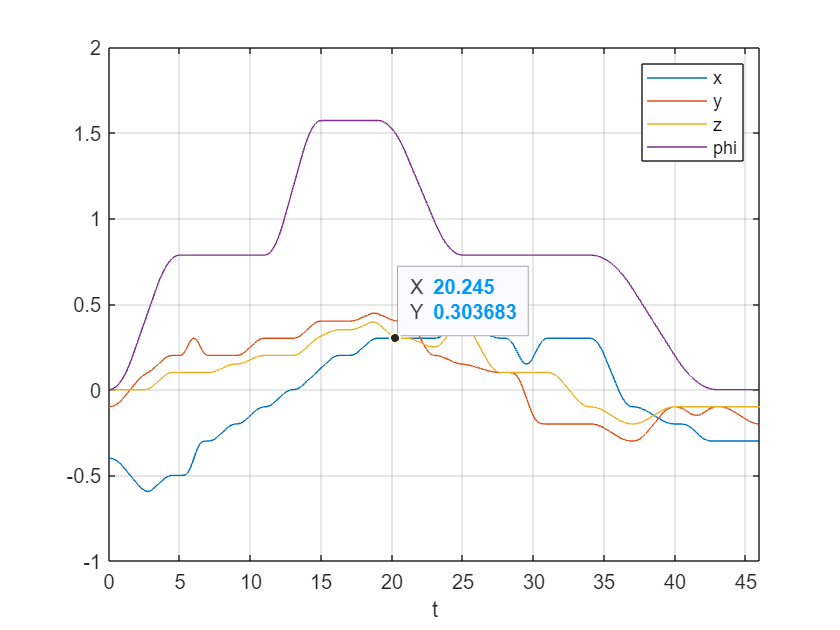


figure
plot(out.controlinvdin.time,out.xeinvdin.signals.values(:,:))
xlabel('t');
xlim([0 t20])
legend('x','y','z','phi')
grid on

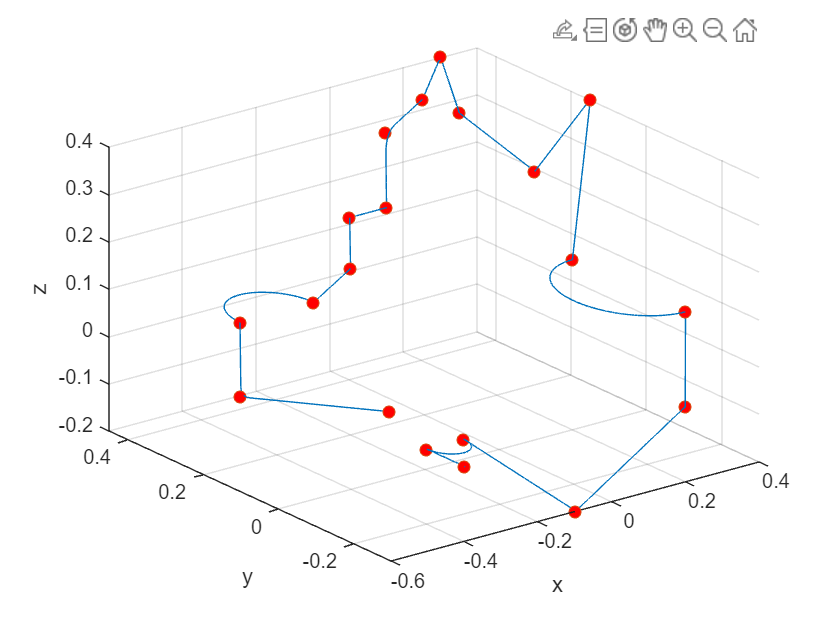

figure
plot3(out.xeinvdin.signals.values(1,:),out.xeinvdin.signals.values(2,:),out.xeinvdin.signals.values(3,:))
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','r')
xlabel('x')
ylabel('y')
zlabel('z')
grid on